### Auteurs

    Alexandre Lamarre  

    Alexandre Desgagné

% Paramètre live script 
    clear all;
    addpath('config/')
    [simulink, simulation, physics, kalman, thrusters, MPC] = ConfigAUV8()
    sympref('MatrixWithSquareBrackets',true);
    s = settings;
    s.matlab.editor.export.pdf.FigureFormat.TemporaryValue = 'svg';

% Generate AUV model fonction for simulink. may take up to 15 min to complete.
   GenModel = true;
    

Si le script est lent sur votre ordinateur, vous pouvez augmenter la taille de la memoire de java. le réponse suivante montre comment procédé.

- [https://www.mathworks.com/matlabcentral/answers/35physics2095-how-can-i-improve-the-speed-of-keyboard-response-in-live-editor#answer_391960](https://www.mathworks.com/matlabcentral/answers/352095-how-can-i-improve-the-speed-of-keyboard-response-in-live-editor#answer_391960)

# Rouler le script dans le dossier src !!!

## Introduction

Dans cette section, nous discuterons de la modélisation mathématique de notre sous-marin. Ceci va nous permettre de concevoir notre contrôleur ainsi que de générer un modèle physique réaliste pour notre simulateur sur « Unity ». Le modèle physique est principalement basé sur le modèle de Fossen présenté dans le livre G*uidance and Control of Ocean Vehicules de *Thor I. Fossen (1994). Dans ce rapport, nous voulons présenter la matière de façon claire et intuitive afin de créer une lecture fluide et de nous familiariser avec les concepts. De plus, nous voulons que ce rapport soit un bon point de départ. Nous ne ferons pas de preuves et nous n'irons pas trop en détail dans les différents concepts. Si vous voulez approfondir vos connaissances, le livre de Thor I. Fossen sur lequel on s'est basé est disponible à la bibliothèque de l'ÉTS. Son code est « VK 543 F67 1994 ».  

- Définition des hypothèses pour réduire la complexité du modèle.

- Définition des référentiels utilisés.

- Définition de la représentation mathématique de l'orientation du sous-marin.

- Déclaration des variables et des constantes utilisées.

- Construction de l'équation cinématique.

- Construction de l'équation dynamique.

- Construction du modèle d'états.

### Hypothèse

Afin de mieux nous guider dans la modélisation de notre sous-marin, nous avons faite trois suppositions afin d'alléger l'équation dynamique. 

Premièrement, notre sous-marin possède une grande rigidité en raison de ses parois en aluminium qui possède une épaisseur allant jusqu'à 10mm. De plus, nos vitesses sont relativement faibles soit autour de 1 m/s. Nous pouvons donc supposer que les déformations dimensionnelles sous l'effet des forces externes sont négligeables. Ceci permet de définir notre sous-marin comme un corps rigide. 

Deuxièmement, les dimensions du bassin de la compétition ne sont pas très grandes. Les déplacements que le sous-marin effectuera seront relativement faibles soit de 1 à 100m et donc négligeables par rapport à la courbure de la terre. Nous pouvons donc présumer que la terre est plate. Ceci va nous permettre d'utiliser un référentiel cartésien (X Y Z) et non le référentiel de la terre (longitude latitude altitude). 

Troisièmement, nous supposons que les forces et moments hydrodynamiques sont complètement découplés. La négligence des effets de couplage va grandement simplifier l'identification des constantes du modèle physique. Dans le livre *Guidance and Control of* *Ocean* *Vehicules* *(section 2.4, p.37),* Thor I. Fossen (1994) explique que dans notre cas, nous pouvons négliger les forces de couplages, car notre sous-marin fonctionne à basse vitesse et qu’il possède 3 plans de symétrie. Dans la section précédente, nous avons vu que l'équipe mécanique a pris en compte ces affirmations et on conçut AUV8 le plus symétrique possible. 

### Définition du référentiel.

Dans le livre *Guidance and Control of Ocean Vehicules (section 2.1, p.6), *Thor I. Fossen (1994) suggère d'utiliser deux référentiels distincts lorsque nous voulons faire l'analyse dynamique d'un véhicule nautique en 6 degrés de liberté (DDL). La figure suivante montre bien les deux référentiels que nous allons utiliser.  

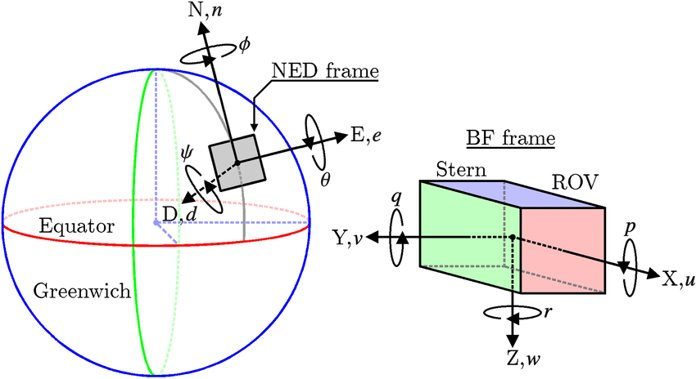

Path Generation for High-Performance Motion of ROVs Based on a Reference Model - Scientific Figure on ResearchGate. Available from: https://www.researchgate.net/figure/NED-and-BF-reference-frames_fig2_277013046 [accessed 26 Jan, 2021]�

Vu que nous supposons que la terre est plate, nous pouvons créer un plan tangent sur la surface de la Terre selon notre position géographique et considérer ce plan pour créer un référentiel cartésien fixe. C'est pour cette raison qu'il est important de calibrer notre IMU lorsque nous allons en compétition. Nous pouvons aussi considérer ce référentiel comme étant inertiel. Un référentiel est inertiel si la somme des forces d’un objet qui se déplace à vitesse constante par rapport à ce référentiel est nulle. Il faut donc que la première loi de Newton soit respectée dans le référentiel pour qu’il soit considéré inertiel.  En outre, nous avons décidé d'utiliser la convention « NED » pour « North East Down » de façon que les axes aient la configuration suivante : 

- X+ : le nord

- Y+ : l'est

- Z+ : le bas

Le référentiel mobile couramment appelé BF pour « Body Fixed » ou référentiel objet est un référentiel qui suit le sous-marin durant ces déplacements. Pour les véhicules mobiles, il est recommandé de placer l'origine de référentiel au centre de masse et que les axes aient la configuration suivante: 

- X : l'axe longitudinal 

- Y : l'axe transversal

- Z : l'Axe normal 

Étant donné que notre référentiel fixe est considéré comme étant inertiel, il est possible de définir la dynamique du référentiel « BF » selon le référentiel fixe. Avec les suppositions que nous venons de définir, dans le livre *Guidance and Control of Ocean Vehicules, *Thor I. Fossen (1994) recommande donc de définir la position et l'orientation en fonction du référentiel inertiel ainsi que les vitesses linéaires et angulaires en fonction du référentiel « BF ». 

### Définition de la représentation de l'orientation

Pour représenter l'orientation du sous-marin, nous avons décidé d'opter pour le quaternion unitaire au lieu des angles d'Euler autant pour des raisons mathématiques que pour des raisons d'implémentation. Même si le quaternion n'est pas aussi intuitif que les angles d'Euler, il possède de gros avantages qui expliquent sa popularité. Afin de concorder avec Matlab, nous avons décidé d'utiliser la convention où la partie scalaire se trouve au début et que la partie imaginaire seconde. Le quaternion s’écrit donc de la façon suivante : 


$$q=\eta +\varepsilon_1 \;\mathit{\mathbf{i}}+\varepsilon_2 \;\mathit{\mathbf{j}}+\varepsilon_1 \;\mathit{\mathbf{k}}$$


D'un point de vue mathématique, vu que le quaternion possède quatre paramètres au lieu de trois, il est en mesure de définir n'importes qu'elles rotation en évitant toute singularité. Ce phénomène est plus connu sous le nom de « Gimbal lock ». De plus, le quaternion ne contient pas de discontinuité. Avec les angles d'Euler, ce problème est plus connu sous « wrap around » et nous pouvons retrouver ce problème lorsqu'un angle approche $\pm \pi$radian. La figure suivante montre ce phénomène.

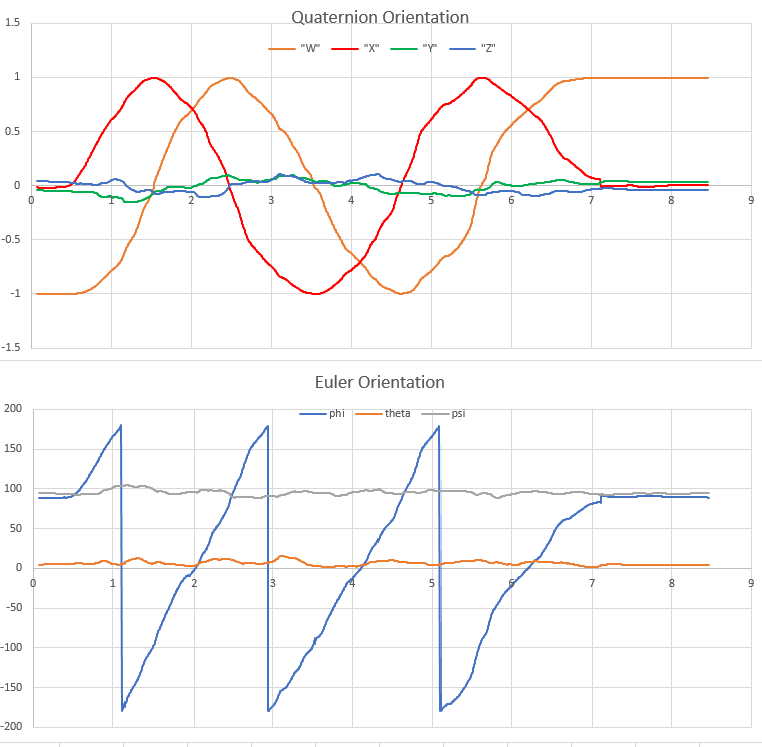

[https://blog.endaq.com/quaternions-for-orientation](https://blog.endaq.com/quaternions-for-orientation)

En ce qui concerne l'implémentation de notre modèle, nous avons avantage à utiliser le quaternion, car il est plus stable numériquement. Ceci explique sa grande popularité dans les applications numériques. La preuve, les logiciels que nous utilisons (ROS, Gazebo, Unity, etc.) utilisent le quaternion. Ceci est une raison supplémentaire pour l’utilisation de celui-ci. Cependant, définir le modèle physique en quaternion n'oblige pas que la commande doive l'utiliser aussi.

### Définition des variables

Dans cette section, nous définirons les variables qui pourront être utiles pour la modélisation. Pour être le plus cohérents possible avec le livre *Guidance and Control of Ocean Vehicules, *Thor I. Fossen (1994), nous utiliserons la même notation que le livre, soit celle définie par SNAME (1950). Le tableau suivant définit les variables liées au degré de liberté. 

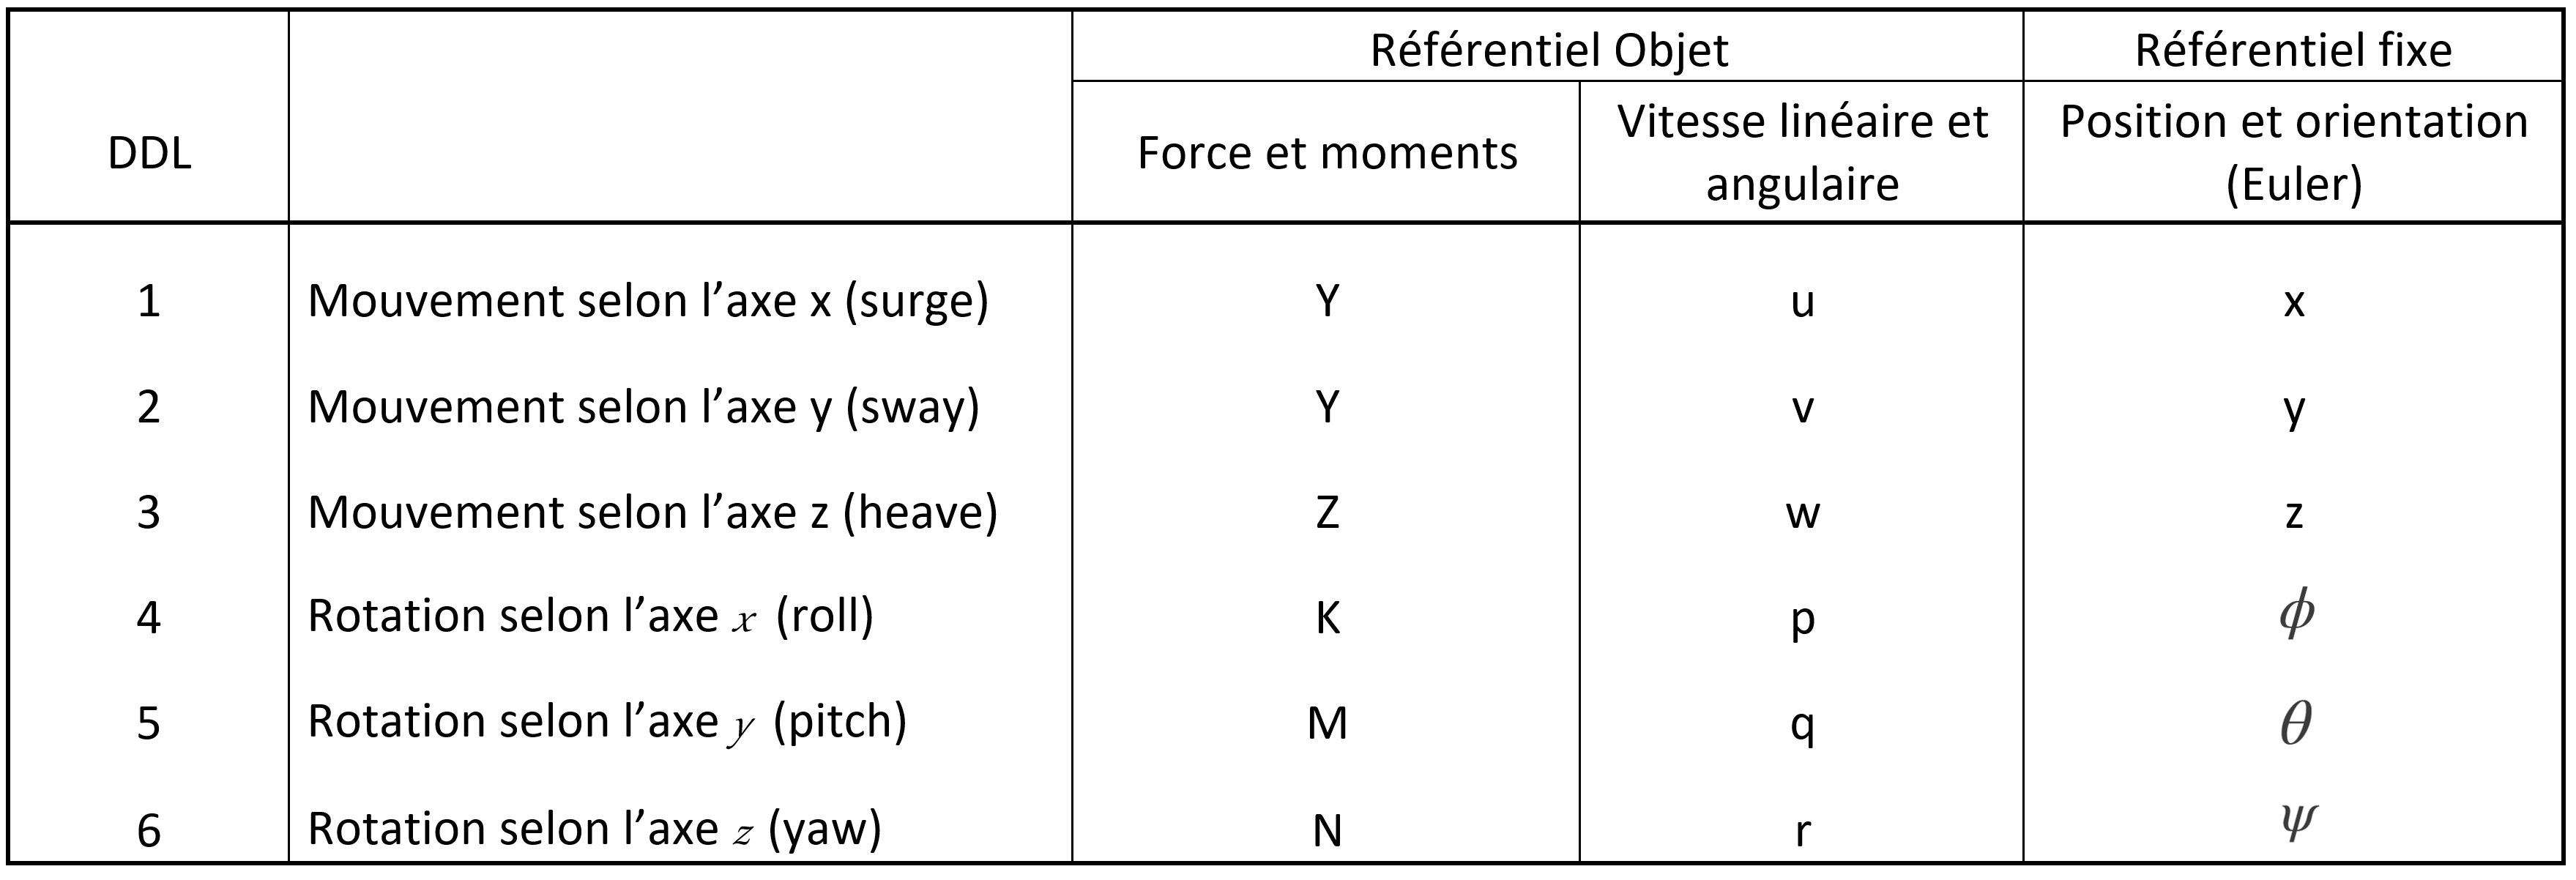

% Définir les forces et moments
    syms X Y Z K MM N
    syms Fm
    syms tauE
    
% Définir les vitesses linéaires et angulaires
    syms u v w p q r

% Définir les positions linéaires
    syms x y z

% Définir les mds
    syms ('m_d',[8,1])
   
% Définir les angle d'euler
    syms phi theta psi

Dans le cadre de ce projet, nous allons utilisé la représentation basé sur le quaternion. Nous pouvons le définire de la façon suivante.


$$\;e={\left\lbrack \eta ,\;\varepsilon_1 ,\;\varepsilon_2 ,{\;\varepsilon }_3 \right\rbrack }^T$$



% Définir la partie scalaire du quaternion
    syms eta;
        
% Définir la partie vectorielle du quaternion
    syms('epsilon',[3,1]);
    
% Définir le quaternion  
     e=[eta; epsilon]; 

    
% Condition Initials
    syms ('Ne_0',[7,1])
    syms ('N_0',[6,1])
    syms ('V_0',[6,1])
    

### Regroupement des variables

Nous allons par la suite regrouper les variables sous la forme vectoriel. nous pouvons définir le vecteur vitesse de la façon suivante


$$\;v\;=\left\lbrack v_1^T ,v_2^T \right\rbrack \;;\;\;\;\;\;\;\;{\;v}_1 ={\left\lbrack u,v,w\right\rbrack }^T ;\;\;\;\;\;\;v_2 ={\left\lbrack p,q,r\right\rbrack }^T ;\;\;$$


% Vitesses
    v1=[u,v,w].';
    v2=[p,q,r].';
    V=[v1;v2]

Nous pouvons définir le vecteur pose avec la représentation d'angle d'euler de la façon suivante.


$$n_e =\left\lbrack n_1^T ,n_2^T \right\rbrack \;;\;\;\;\;\;\;\;n_1 ={\left\lbrack x,y,z\right\rbrack }^T ;\;\;\;\;\;\;\;n_2 ={\left\lbrack \phi ,\theta ,\psi \right\rbrack }^T ;\;\;$$
  

% vecteur pose selon euler
     n1 = [x,y,z].';
     n2 = [phi, theta, psi].';
     Ne = [n1;n2];

Nous pouvons aussi définir le vecteur pose avec la représentation des quaternions de la façon suivante.


$$n_q =\left\lbrack n_1^T ,e^T \right\rbrack \;;\;\;\;\;\;\;\;$$
  

% vecteur pose selon les quaternions
    Nq =[n1;e];
   
% Forces et moments
    Fm=[X,Y,Z,K,MM,N].';

### Constante du modèle physique

Dans cette section nous allons définire les constantes mécaniques qui vont nous être utiles pour la modélisation du sous-marin. Le tableau suivant montre les constantes necéssaire pour bien décrire le corp rigide.

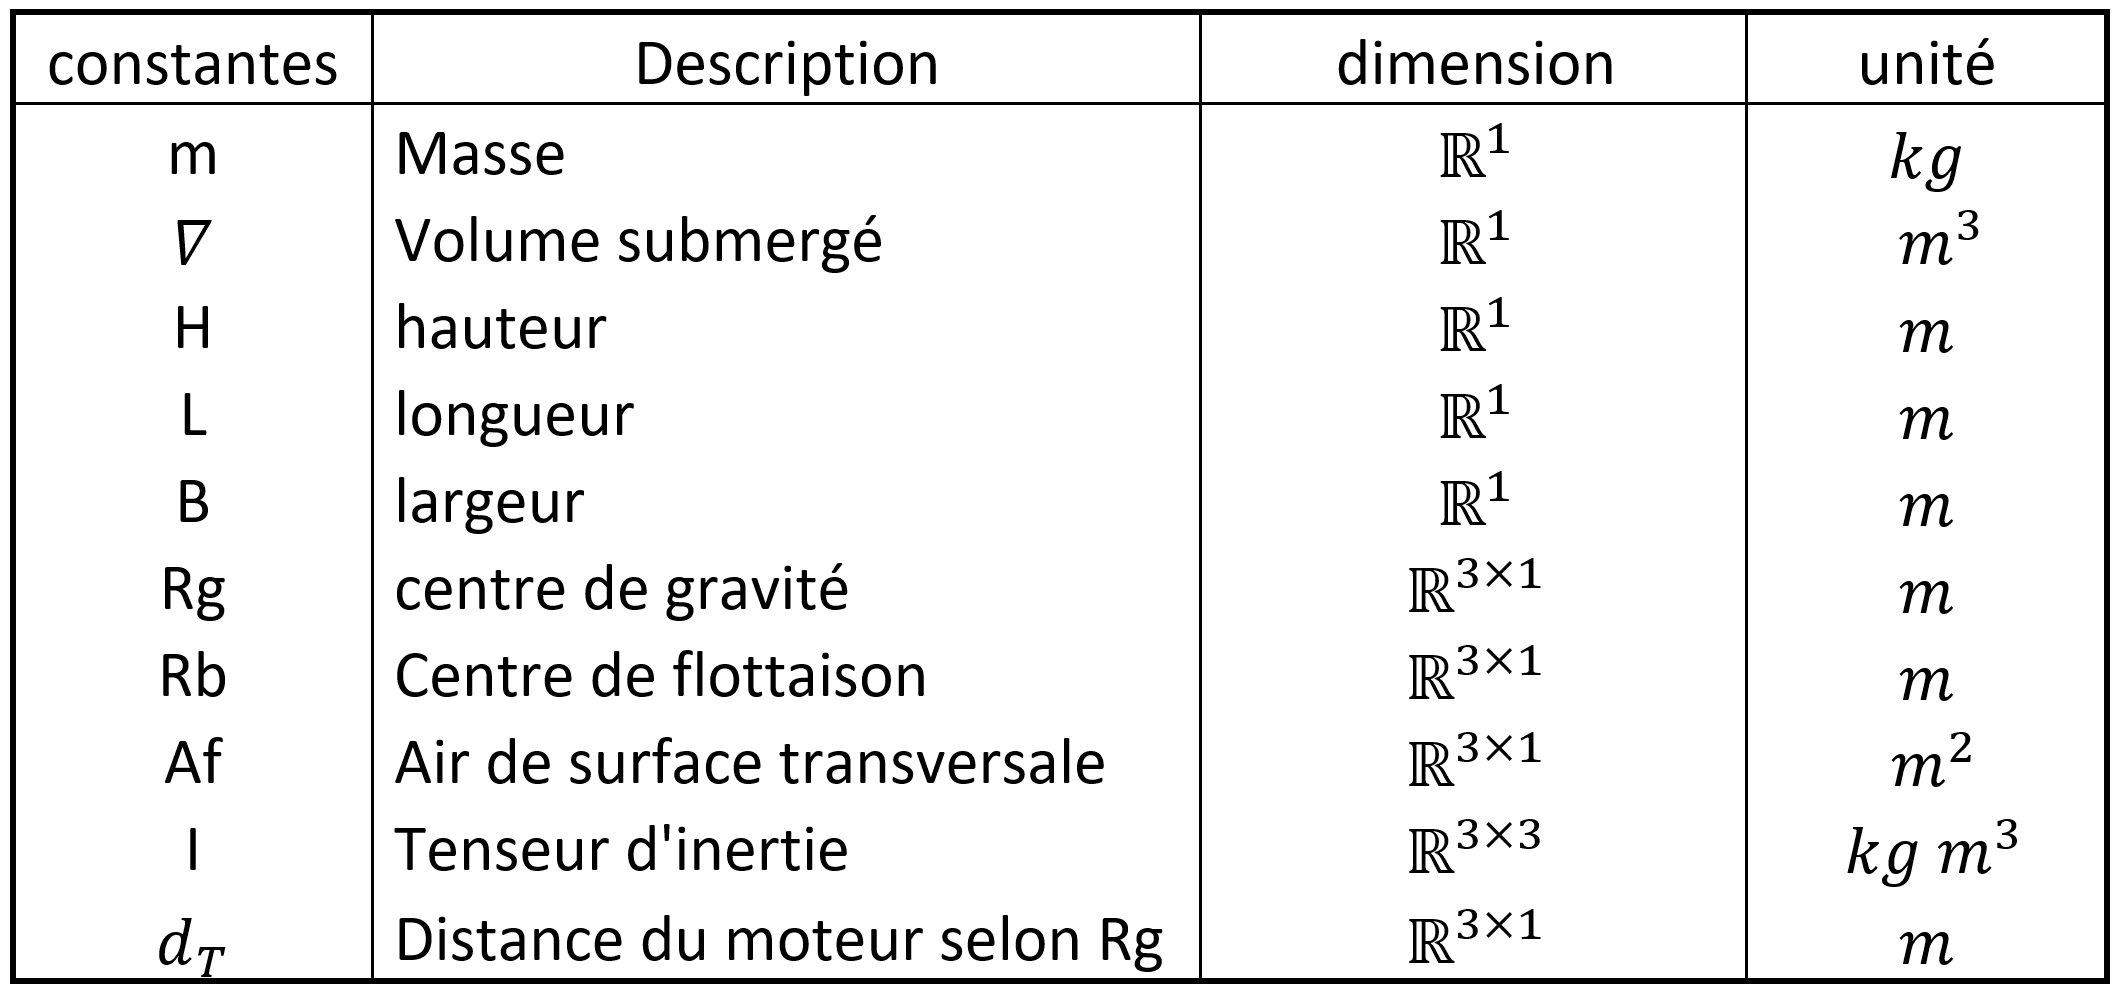

% distance truster x y z selon centre geommétrique (Constantes)
    syms ('d_T',[3 1]);
% masse, volume du prototype et hauteur sub (Constantes)
    syms m volume H L B
    
% Masse Ajoutée
    syms X_u_dot Y_v_dot Z_w_dot K_p_dot M_q_dot N_r_dot
    addedMass = [X_u_dot Y_v_dot Z_w_dot K_p_dot M_q_dot N_r_dot];
    
% coefficient de drag (Constantes)
    syms ('CD_L',[1, 6])    % Lineaire
    syms ('CD_Q', [1, 6]);  % Quadratique

% aire de surface du sub (Constantes)
    syms ('AF', [1, 3]);

% matrice d'inertie (Constantes)
    syms ('I', [3, 3]);

% centre de gravité RG et centre de flotataison RB (Constantes)
    syms ('RG',[3 1]); syms('RB',[3 1])
    
% Constantes physique (densité de leau et accélération gravitationel)
    syms rho g
    
% Constance Mecanique
   constMec = [m volume H ...
             I(1,:) I(2,:) I(3,:) RG.' RB.' CD_L CD_Q addedMass rho g];


## Équation cinématique du mouvement 

Dans cette section, nous allons définir l'équation différentielle de la cinématique du sous-marin. Cette équation transforme les vitesses linéaires et angulaires du référentiel objet au référentiel inertiel. De plus, les vitesses angulaires seront transformées afin de pouvoir être intégrées dans leur représentation respective. De cette façon, nous serons en mesure de déterminer la position et l'orientation du sous-marin par rapport au référentiel fixe. Cette section est importante, car tous les capteurs présents sur le sous-marin donnent les valeurs dans le référentiel objet. Il nous est donc impossible de mesurer les états du sous-marin directement à partir du référentiel fixe. La figure suivante montre la relation entre les variables liées au référentiel objet et ceux du référentiel fixe. 

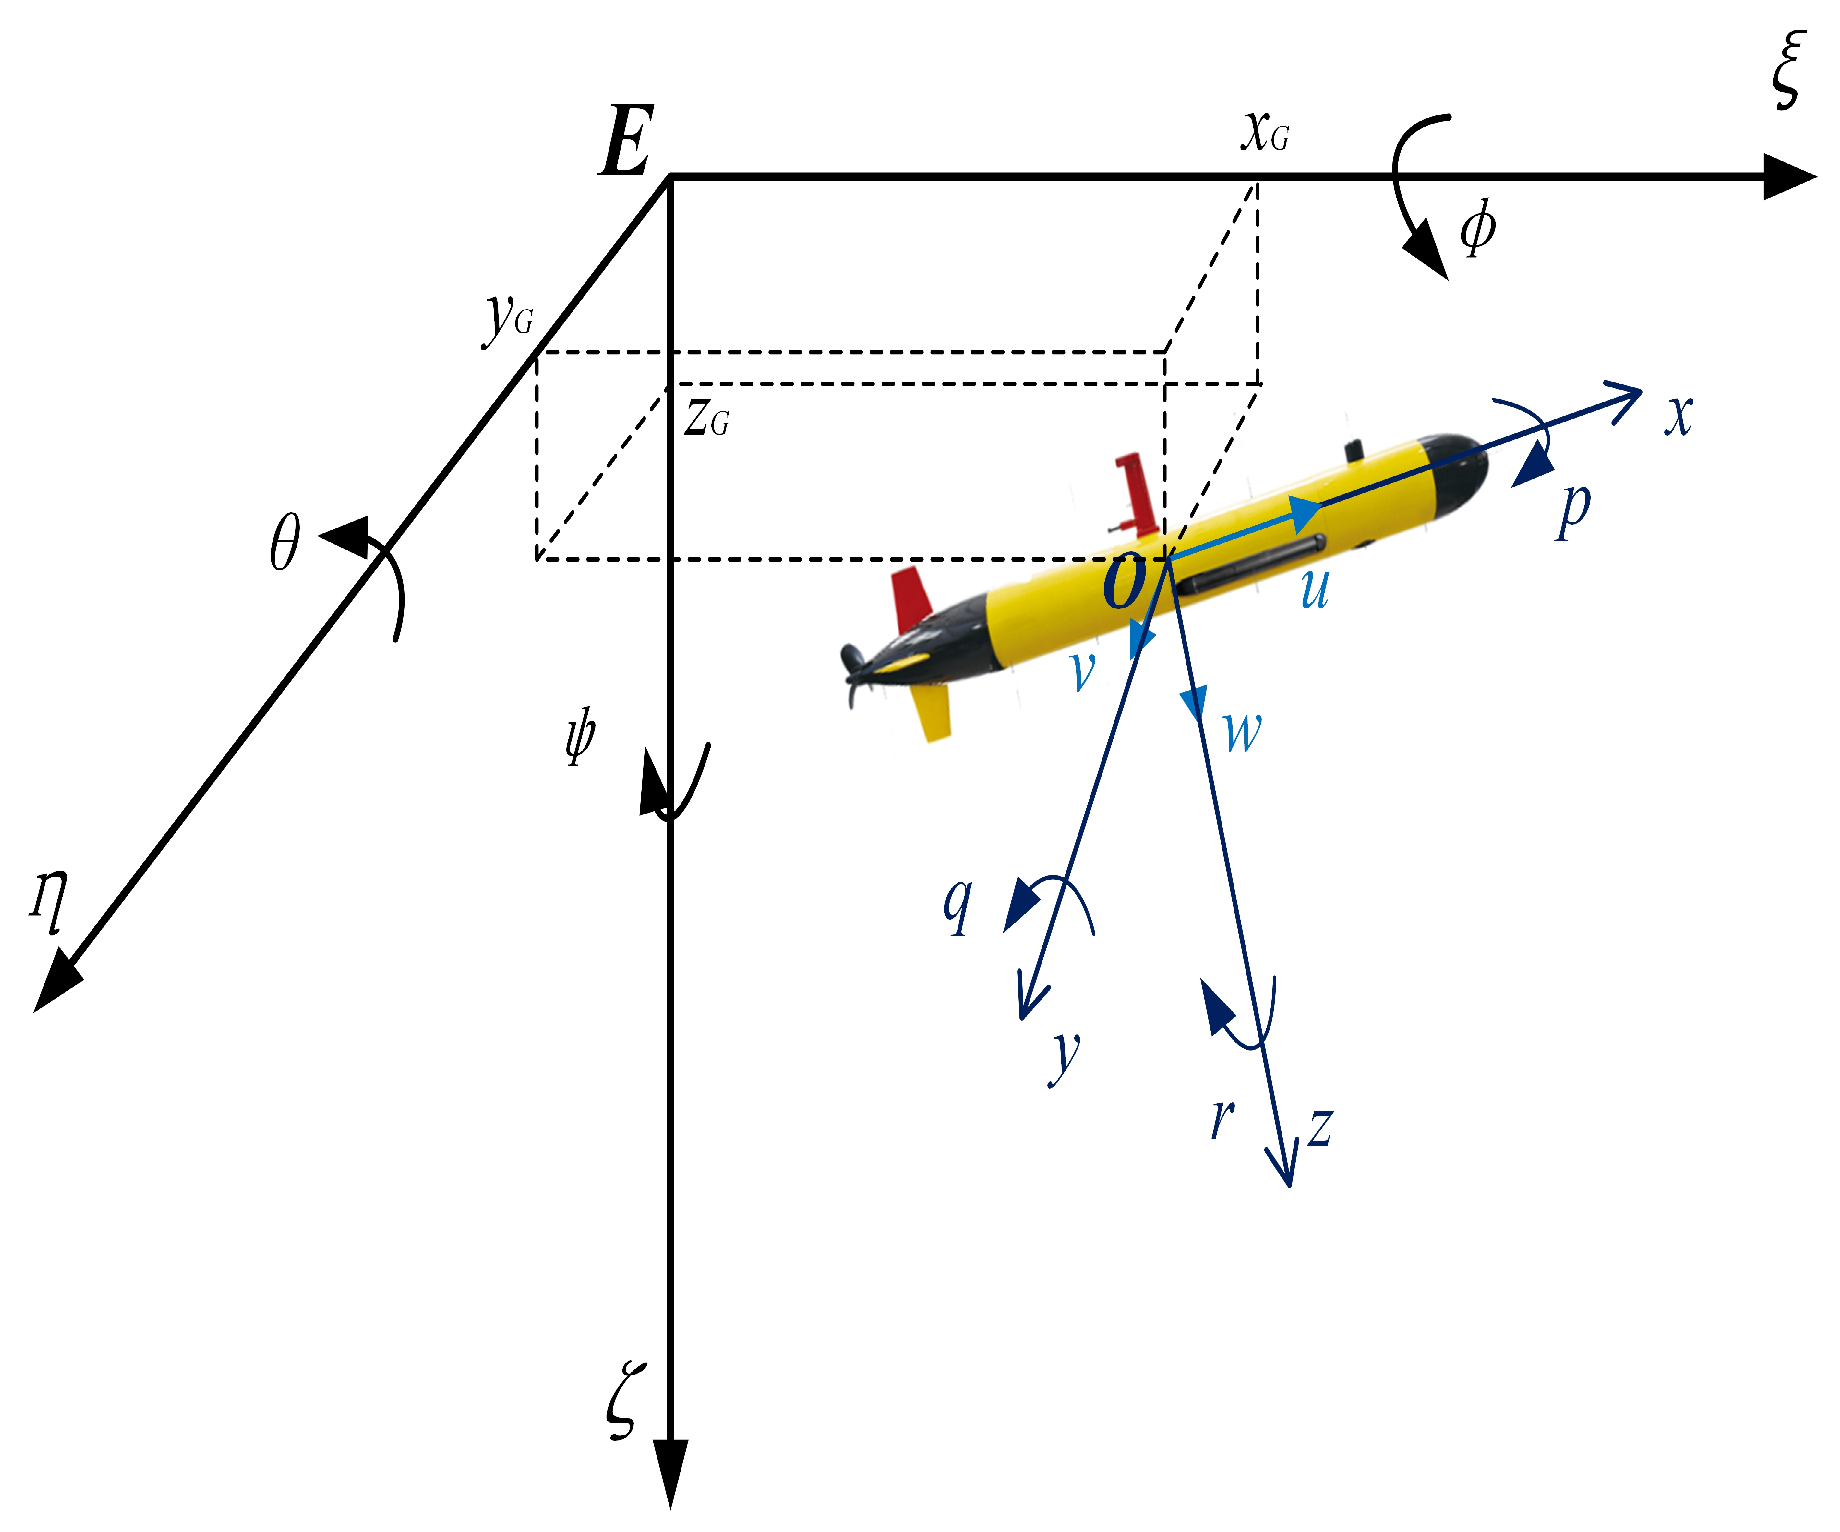

https://www.mdpi.com/2076-3417/9/17/3518/htm#B31-applsci-09-03518

Nous commencerons par définir l'équation différentielle cinématique avec la représentation d'angle d'Euler, car la plupart des concepts utilisés sont abordés dans le cours GPA546. Il sera plus facile de comprendre l'idée derrière cette formule avant de construire la même équation cinématique, mais en utilisant les quaternions. 

### Équation cinématique du mouvement représenté avec les angles d'Euler

Dans cette section, nous définirons une équation cinématique utilisant les angles d'Euler. Nous allons utiliser l'ordre de rotation ZYX. Nous pouvons exprimer cette équation différentielle sous la forme matricielle suivante. 


$${\dot{n} }_e =J\left(n_e \right)v\;\iff \left\lbrack \begin{array}{c}
{\dot{n} }_1 \\
{\dot{n} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
J_1 \left(n_2 \right) & 0_{3\textrm{x3}} \\
0_{3\textrm{x3}}  & J_2 \left(n_2 \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_1 \\
v_2 
\end{array}\right\rbrack \;{\;\in \mathbb{R}}^6$$


Afin d'allèger l'écriture des matrices, nous allons utiliser la notation « c » pour le cosinus, « s » pour le sinus et « t » pour la tangente.

#### Transformation de la vitesse linéaire

Dans cette section, nous allons déterminer la transformation de la vitesse linéaire, soit la matrice $J_1$. Dans un premier temps, il faut définir les matrice de rotation de base pour chaques axes de rotation.


$$R_{x,\phi } =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & c\left(\phi \right) & s\left(\phi \right)\\
0 & -s\left(\phi \right) & c\left(\phi \right)
\end{array}\right\rbrack \;\;$$
   
$$R_{y,\theta } =\left\lbrack \begin{array}{ccc}
c\left(\theta \right) & 0 & -s\left(\theta \right)\\
0 & 1 & 0\\
s\left(\theta \right) & 0 & c\left(\theta \right)
\end{array}\right\rbrack$$
     
$$R_{z,\psi } =\left\lbrack \begin{array}{ccc}
c\left(\psi \right) & s\left(\psi \right) & 0\\
-s\left(\psi \right) & c\left(\psi \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


% Angle Euler Z Y X
    Rz = [ cos(psi), sin(psi), 0;
           -sin(psi),  cos(psi), 0;
           0        ,  0        , 1];
       
    Ry = [ cos(theta), 0,  -sin(theta);
           0          , 1,  0;
          sin(theta), 0,  cos(theta)];
      
    Rx = [1, 0        , 0;
          0, cos(phi), sin(phi);
          0, -sin(phi), cos(phi)];

Maintenant, si nous voulons la matrice de rotation qui suit l'ordre ZYX, il suffit de multiplier les transposés des matrices de rotation de base dans le même ordre. Il faut se rappeler que le produit des matrices de rotation n'est pas commutatif. L'ordre est donc très important. Cela donne l’équation suivante : 


$$J_1 \left(n_2 \right)={R_{z,\psi } }^T {R_{y,\theta } }^T {R_{x,\phi } }^T$$


Nous pouvons développer cette équation, ce qui nous donne:


$$J_1 \left(n_2 \right)=\left\lbrack \begin{array}{ccc}
c\left(\psi \right)\,c\left(\theta \right) & c\left(\psi \right)\,s\left(\phi \right)\,s\left(\theta \right)-c\left(\phi \right)\,s\left(\psi \right) & s\left(\phi \right)\,s\left(\psi \right)+c\left(\phi \right)\,c\left(\psi \right)\,s\left(\theta \right)\\
c\left(\theta \right)\,s\left(\psi \right) & c\left(\phi \right)\,c\left(\psi \right)+s\left(\phi \right)\,s\left(\psi \right)\,s\left(\theta \right) & c\left(\phi \right)\,s\left(\psi \right)\,s\left(\theta \right)-c\left(\psi \right)\,s\left(\phi \right)\\
-s\left(\theta \right) & c\left(\theta \right)\,s\left(\phi \right) & c\left(\phi \right)\,c\left(\theta \right)
\end{array}\right\rbrack$$


% Matrice de transformation vitesse liéaire du frame sub au frame world
    J1 = simplify(Rz.' *Ry.' *Rx.');

#### Transformation de la vitesse angulaire

Dans cette section, nous définirons une relation pour transformer les vitesses angulaires du référentiel objet $v_2 ={\left\lbrack p,q,r\right\rbrack }^T$en vecteur de rotation instantané $\dot{n_2 } ={\left\lbrack \dot{\phi} ,\dot{\theta} ,\dot{\psi} \right\rbrack }^T$. Nous pouvons définir une matrice de transformation $J_2$ pour nous permettre cette transformation. Ce qui donne:


$${\dot{n} }_2 =J_2 \left(n_2 \right){\;v}_2$$


Comparativement à des vitesses linéaires, nous ne pouvons pas directement intégrer les vitesses angulaires $v_2 ={\left\lbrack p,q,r\right\rbrack }^T$ afin d'obtenir son orientation. Cependant il possible d'intégré un vecteur de rotation instantané  $\dot{n_2 } ={\left\lbrack \dot{\phi} ,\dot{\theta} ,\dot{\psi} \right\rbrack }^T$ afin d'obtenir l'orientation du sous-marin dans le référentiel inertiel. Pour effectuer cette  conversion nous pouvons utiliser la relation suivante.

$v_2 =\left\lbrack \begin{array}{c}
\dot{\phi} \\
0\\
0
\end{array}\right\rbrack +$$R_{x,\phi }$$\left\lbrack \begin{array}{c}
0\\
\dot{\theta} \\
0
\end{array}\right\rbrack$+ $R_{x,\phi }$$R_{y,\theta }$$\left\lbrack \begin{array}{c}
0\\
0\\
\dot{\psi} 
\end{array}\right\rbrack =J_2^{-1} \left(n_2 \right){\dot{n} }_2$

Nous pouvons développer cette relation afin de déterminer la matrice $J_2^{-1}$ puis l'inverser pour avoir la matrice $J_2$.


$$J_2^{-1} =\left\lbrack \begin{array}{ccc}
1 & 0 & -s\left(\theta \right)\\
0 & c\left(\phi \right) & c\left(\theta \right)\,s\left(\phi \right)\\
0 & -s\left(\phi \right) & c\left(\phi \right)\,c\left(\theta \right)
\end{array}\right\rbrack \;\;\;\Rightarrow \;\;\;\;J_2 =\left\lbrack \begin{array}{ccc}
1 & \frac{s\left(\phi \right)\,s\left(\theta \right)}{c\left(\theta \right)} & \frac{c\left(\phi \right)\,s\left(\theta \right)}{c\left(\theta \right)}\\
0 & c\left(\phi \right) & -s\left(\phi \right)\\
0 & \frac{s\left(\phi \right)}{c\left(\theta \right)} & \frac{c\left(\phi \right)}{c\left(\theta \right)}
\end{array}\right\rbrack$$


% Calcule de la matrice J2 inverse
    J2inv= [[1,0,0].',Rx*[0,1,0].',Rx*Ry*[0,0,1].'];
% Calcule de la matrice J2
    J2=simplify(inv(J2inv));

#### Matrice de transformation

Nous avons donc tous éléments nécéssaire pour construire notre matrice J. Nous pouvons la développer, ce qui donne le résultat suivant. 


$$J=\left\lbrack \begin{array}{cccccc}
c\left(\psi \right)\,c\left(\theta \right) & c\left(\psi \right)\,s\left(\phi \right)\,s\left(\theta \right)-c\left(\phi \right)\,s\left(\psi \right) & s\left(\phi \right)\,s\left(\psi \right)+c\left(\phi \right)\,c\left(\psi \right)\,s\left(\theta \right) & 0 & 0 & 0\\
c\left(\theta \right)\,s\left(\psi \right) & c\left(\phi \right)\,c\left(\psi \right)+s\left(\phi \right)\,s\left(\psi \right)\,s\left(\theta \right) & c\left(\phi \right)\,s\left(\psi \right)\,s\left(\theta \right)-c\left(\psi \right)\,s\left(\phi \right) & 0 & 0 & 0\\
-s\left(\theta \right) & c\left(\theta \right)\,s\left(\phi \right) & c\left(\phi \right)\,c\left(\theta \right) & 0 & 0 & 0\\
0 & 0 & 0 & 1 & \frac{s\left(\phi \right)\,s\left(\theta \right)}{c\left(\theta \right)} & \frac{c\left(\phi \right)\,s\left(\theta \right)}{c\left(\theta \right)}\\
0 & 0 & 0 & 0 & c\left(\phi \right) & -s\left(\phi \right)\\
0 & 0 & 0 & 0 & \frac{s\left(\phi \right)}{c\left(\theta \right)} & \frac{c\left(\phi \right)}{c\left(\theta \right)}
\end{array}\right\rbrack$$


Nous pouvons remarquer que cette matrice n'est pas défini pour l'ensemble des angles  $\theta \in \left\lbrack -\pi ,\pi \right\rbrack$. En effet, nous pouvons constater que nous avons des divisions par 0 losque l'angle $\theta$(pitch) vaut $\pm \frac{\pi }{2}$radians. Ceci crée alors des zones de singularités. Ceci n'est pas une surprise car toutes les représentations d'orientation à trois paramètres contiens des zone singulière. Cependant,  la plupart des aplications martime ne travail pas autours des zones de singularités que nous avons déterminé. Il est donc possible d'utiliser cette représenation dans notre application. 

% Définir la matrice de transformation J(ne)
    J=[J1,zeros(3,3);
    zeros(3,3),J2];

### Équation cinématique représenté avec le quaternion unitaire

s cette section nous allons définir l'équation cinématique basée sur le quaternion. L'équation différentielle va avoir la même forme que pour les angles d'Euler, mais la matrice ne sera plus carrée, car le quaternion contient quatre paramètres. Cela donne l’équation suivante:


$${\dot{n} }_q =E\left(n_q \right)v\;\iff \left\lbrack \begin{array}{c}
{\dot{n} }_1 \\
\dot{e} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
E_1 \left(e\right) & 0_{3\textrm{x3}} \\
0_{4\textrm{x3}}  & E_2 \left(e\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_1 \\
v_2 
\end{array}\right\rbrack \;{\;\in \mathbb{R}}^7$$


#### Transformation de la vitesse linéaire

Dans cette section, nous allons déterminer la transformation de la vitesse linéaire. Cette équation prend la forme suivante:


$$\dot{n} =E_1 \left(e\right){\;v}_1$$


Nous pouvons transformer un vecteur d'un référentiel à un autre en fonction d'un quaternion décrivant la transformation entre les deux référentiels en utilisant la relation suivante.


$$E_1 =I_{3\textrm{X3}\;} +2\eta \mathit{\mathbf{S}}\left(\varepsilon \right)+2{\mathit{\mathbf{S}}}^2 \left(\varepsilon \right)$$


Ou $I_{3\textrm{X3}\;}$est une matrice identitaire et **S **est une matrice anti symétrique ${\mathbb{R}}^{3\textrm{x3}}$.

Nous pouvons développer la relation précédente pour l'avoir sous la forme matriciel. 


$$E_1 =\left\lbrack \begin{array}{ccc}
-2\,{\varepsilon_2 }^2 -2\,{\varepsilon_3 }^2 +1 & 2\,\varepsilon_1 \,\varepsilon_2 -2\,\varepsilon_3 \,\eta  & 2\,\varepsilon_1 \,\varepsilon_3 +2\,\varepsilon_2 \,\eta \\
2\,\varepsilon_1 \,\varepsilon_2 +2\,\varepsilon_3 \,\eta  & -2\,{\varepsilon_1 }^2 -2\,{\varepsilon_3 }^2 +1 & 2\,\varepsilon_2 \,\varepsilon_3 -2\,\varepsilon_1 \,\eta \\
2\,\varepsilon_1 \,\varepsilon_3 -2\,\varepsilon_2 \,\eta  & 2\,\varepsilon_2 \,\varepsilon_3 +2\,\varepsilon_1 \,\eta  & -2\,{\varepsilon_1 }^2 -2\,{\varepsilon_2 }^2 +1
\end{array}\right\rbrack$$


% Équation E1
    E1=eye(3)+2*eta*skew(epsilon)+2*skew(epsilon)^2;   

#### Transformation de la vitesse angulaire

Dans cette section, nous allons définir l'équation de la transformation de la vitesse angulaire, Cette équation prend la forme suivante:


$$\dot{e} =E_2 \left(e\right){\;v}_2$$


 De la même façon que pour les angles d'Euler, nous devons transformé les vitesse angulaire du référentiel objet $v_2 ={\left\lbrack p,q,r\right\rbrack }^T$ en quaternion instantané $\dot{e} =\left\lbrack \dot{\eta} \;\;\;{\dot{\varepsilon} }_1 \;{\dot{\;\varepsilon } }_2 \;{\dot{\varepsilon} }_3 \right\rbrack$  afin d'être en mesure de l'intégré dans le référentiel fixe. Pour effectuer cette conversion, nous pouvons utiliser la relation suivante.


$$E_2 =\frac{1}{2}\left\lbrack \begin{array}{ccc}
-\varepsilon_1  & -\varepsilon_2  & -\varepsilon_3 \\
\eta  & -\varepsilon_3  & \varepsilon_2 \\
\varepsilon_3  & \eta  & -\varepsilon_1 \\
-\varepsilon_2  & \varepsilon_1  & \eta 
\end{array}\right\rbrack$$


% Équation E2
     E2=(1/2)*[-epsilon.';eta*eye(3)+skew(epsilon)];

#### Matrice de transformation

Nous avons donc tous éléments nécéssaire pour construire notre matrice E. Nous pouvons la développer, ce qui donne le résultat suivant. 


$$E=\left\lbrack \begin{array}{cccccc}
-2\,{\varepsilon_2 }^2 -2\,{\varepsilon_3 }^2 +1 & 2\,\varepsilon_1 \,\varepsilon_2 -2\,\varepsilon_3 \,\eta  & 2\,\varepsilon_1 \,\varepsilon_3 +2\,\varepsilon_2 \,\eta  & 0 & 0 & 0\\
2\,\varepsilon_1 \,\varepsilon_2 +2\,\varepsilon_3 \,\eta  & -2\,{\varepsilon_1 }^2 -2\,{\varepsilon_3 }^2 +1 & 2\,\varepsilon_2 \,\varepsilon_3 -2\,\varepsilon_1 \,\eta  & 0 & 0 & 0\\
2\,\varepsilon_1 \,\varepsilon_3 -2\,\varepsilon_2 \,\eta  & 2\,\varepsilon_2 \,\varepsilon_3 +2\,\varepsilon_1 \,\eta  & -2\,{\varepsilon_1 }^2 -2\,{\varepsilon_2 }^2 +1 & 0 & 0 & 0\\
0 & 0 & 0 & -\frac{\varepsilon_1 }{2} & -\frac{\varepsilon_2 }{2} & -\frac{\varepsilon_3 }{2}\\
0 & 0 & 0 & \frac{\eta }{2} & -\frac{\varepsilon_3 }{2} & \frac{\varepsilon_2 }{2}\\
0 & 0 & 0 & \frac{\varepsilon_3 }{2} & \frac{\eta }{2} & -\frac{\varepsilon_1 }{2}\\
0 & 0 & 0 & -\frac{\varepsilon_2 }{2} & \frac{\varepsilon_1 }{2} & \frac{\eta }{2}
\end{array}\right\rbrack$$


Nous pouvons remarquer que cette matrice est définie pour l'ensemble des valeurs $\left\lbrack \eta ,\;\varepsilon_1 ,\;\varepsilon_2 ,{\;\varepsilon }_3 \right\rbrack \in \left\lbrack -1,1\right\rbrack$. Par conséquent, la matrice de transformation E ne contient aucune zone de singularité. Cependant nous rajoutons un quatrième paramètre. Nous pouvons aussi constater que la Matrice E ne contient que des multiplications et des additions, ce qui est plus stable numériquement que des fonctions trigonométriques. De plus, nous pouvons remarquer que la matrice $E_2$ est plus linéaire que la matrice $J_2$.

% Définir la matrice de transformation E(nq)
   E=[E1,zeros(3,3);
       zeros(4,3),E2];

% Calculs de E*

    E_dot= jacobian(E*V,Nq);


#### Normalisation du quaternion

Il ne faut pas oublier qu'une rotation est considérée pure (que la transformation ne contient aucune déformation) seulement si le quaternion est unitaire. Lorsque nous implémentons le quaternion dans des contextes réels, plusieurs phénomènes comme le bruit ou les erreurs d'arrondissement numérique font en sorte que le quaternion ne soit plus unitaire. Il important de normaliser le quaternion provenant de la IMU et celui intégré par le modèle physique afin de respecter la contrainte du quaternion unitaire, soit : 


$$e^T e=\eta^2 +\varepsilon_1^2 +\varepsilon_2^2 +\varepsilon_3^2 =1$$


Afin de normaliser un quaternion, nous pouvons utiliser la relation suivante.


$$e_{\textrm{normalisé}\;} =\frac{e}{\left\|e\right\|}$$


 L'erreur sur courte période peut être négligeable, mais empire avec le temps.

## Équation dynamique d'un corps rigide

Dans cette section, nous allons développer l'équation différentielle dynamique du sous-marin. Nous avons décidé d'utiliser la représentation de Newton, car elle est intuitive et bien connue par tous les étudiants de l'ÉTS. Étant donné que nos deux référentiels sont cartésiens, il sera facile d'utiliser la représentation de vectoriel. De plus, la représentation de Newton est compatible avec une orientation décrite en quaternion. Nous n'avons pas avantage à utiliser une approche énergétique comme celle de Lagrange. 

Le modèle de Fossen que nous avons utilisé dans ce projet est basé sur la formulation de Newton-Euler. Cette représentation décrit la dynamique en 6 dégrée de liberté (soit en translation et en rotation) sous forme matricielle d'un corps rigide dans l'espace. Il nous est possible d'utiliser cette relation, car nous avons supposé que notre sous-marin soit corps rigide. De plus, vu que la plupart des forces sont décrites selon le référentiel objet, l'équation dynamique sera donc exprimée selon ce référentiel. Le modèle de Fossen peut donc être écrit de la façon suivante. 

## 
$$M\dot{v} +C\left(v\right)y+D\left(v\right)v+g\left(n\right)=\tau$$


    Ou:

        M : La matrice d'inertie du sous-marin (incluant la masse ajoutée) ${\mathbb{R}}^{6\textrm{x6}}$.

        C : La matrice Coriolis ${\mathbb{R}}^{6\textrm{x6}}$

        D : Matrice d'amortissement ${\mathbb{R}}^{6\textrm{x6}}$

        g : Vecteur gravité ${\mathbb{R}}^{6\textrm{x1}}$

        $\tau$: Vecteur de la comamnde ${\mathbb{R}}^{6\textrm{x1}}$.

Cette équation va nous être utiles afin de développer un algorithme de contrôle. Nous allons aussi définir une autre équation qui sera utiliser pour notre simulateur. Nous allons reprendre l'équation précédente en rajoutant des perturbations externes. Cela donne la relation suivante : 

## 
$$M\dot{v} +C\left(v\right)y+D\left(v\right)v+g_b \left(n\right)=\tau_E +\tau$$


Ou:

$g_b$ : Vecteur gravité borné ${\mathbb{R}}^{6\textrm{x1}}$

$\tau_E$ : Vecteur perturbation causé par l'environement ${\mathbb{R}}^{6\textrm{x1}}$.

% Définir les forces externes et perturbations
    syms ('F_ext',[6,1]);

Nous allons discuter de chaques élément de l'équation dans les prochaines sous-sections.

### Matrice d'inertie

Dans cette section, nous allons définir la matrice M de l'équation dynamique. Dans notre contexte, la masse du fluide ne peut pas être négligée. La masse du système sera donc la masse du sous-marin plus la masse virtuelle de l'eau déplacée. La figure suivante montre la répartition de la masse ajoutée qui entoure le sous-marin lorsqu'il se déplace. 

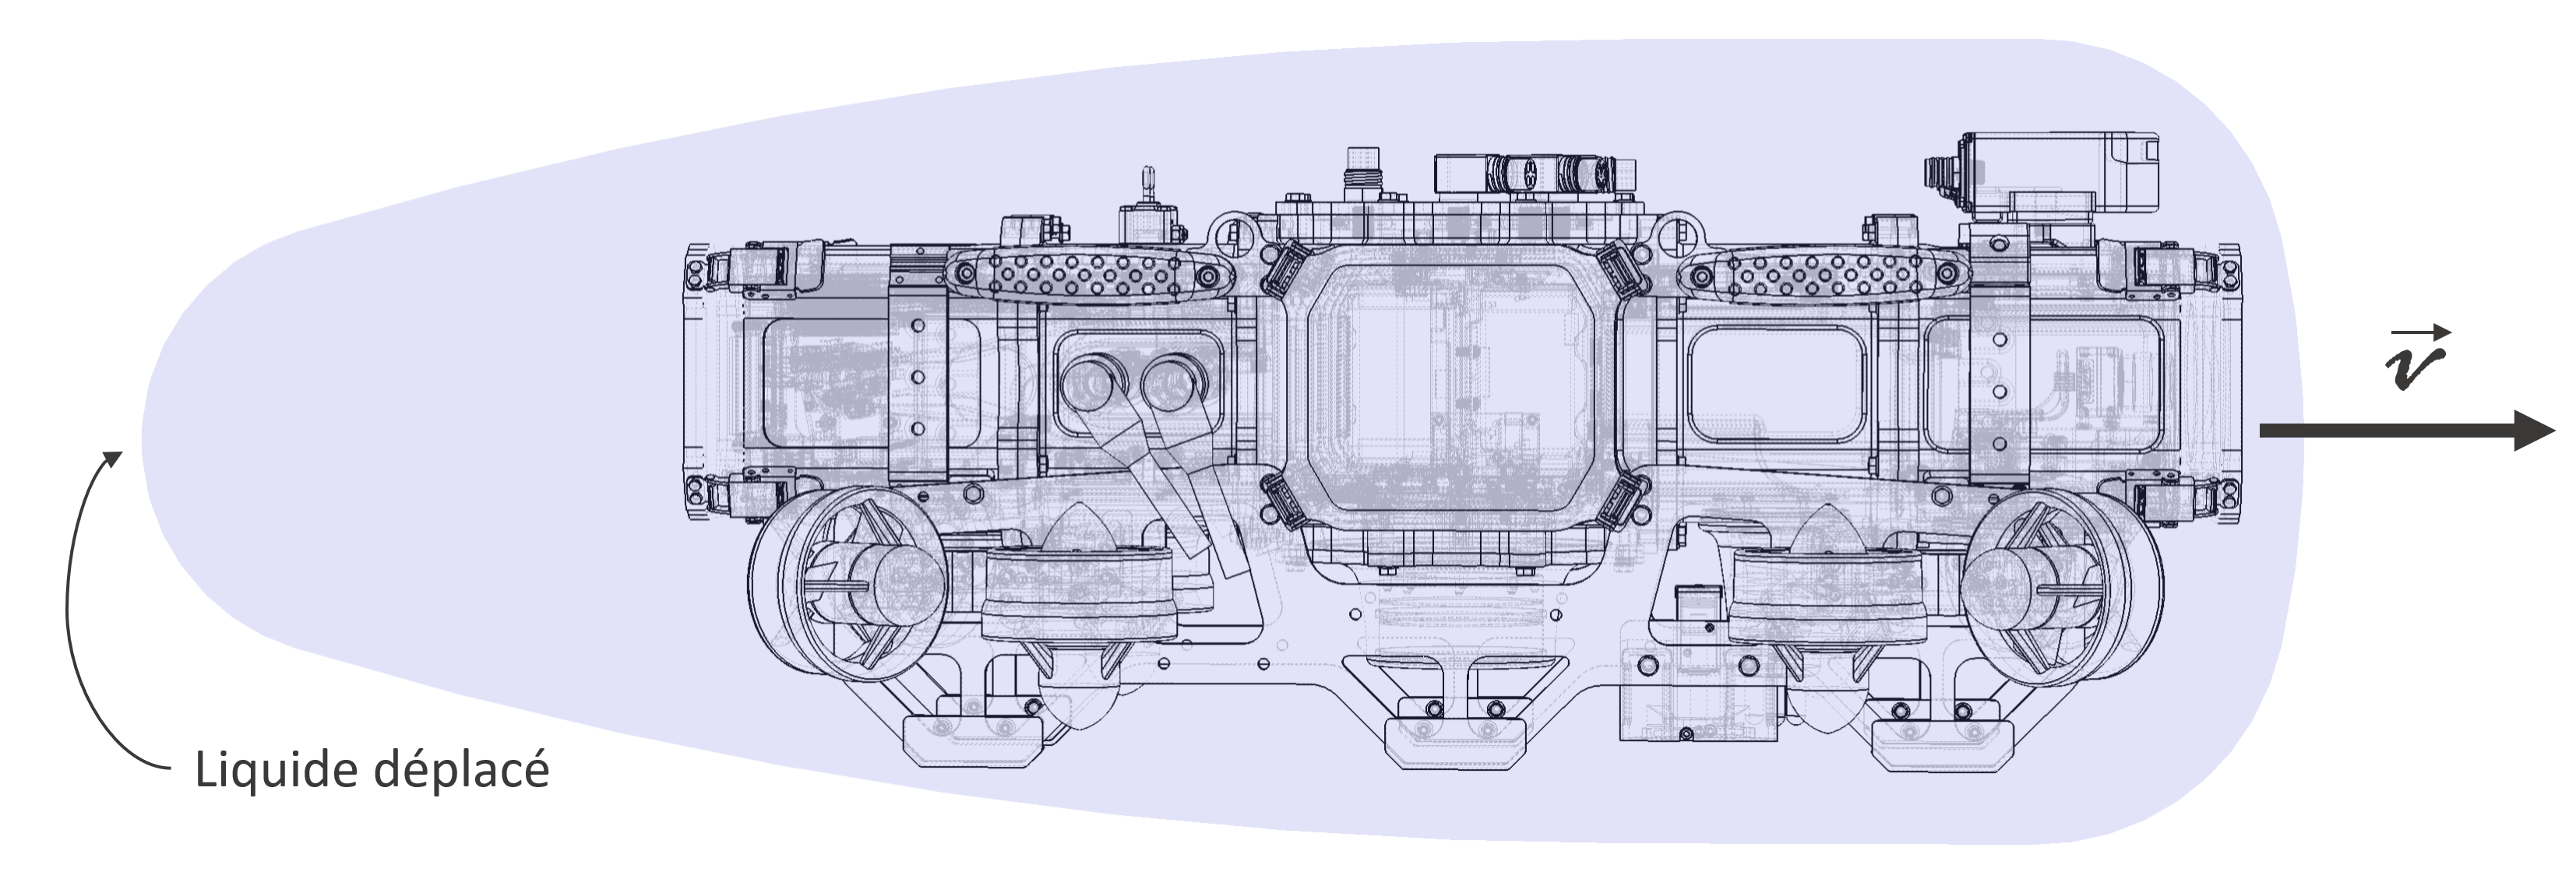

Dans le livre *Guidance and Control of Ocean Vehicules *(section 2.4.1 p.32)*, *Thor I. Fossen (1994) explique que si nous voulons être rigoureux nous ne pourrions pas définir le système comme une masse plus lourde puisque ce concept est faux. Cependant, vu que nous négligeons plusieurs paramètres, cette affirmation devient acceptable. Cette matrice se trouve à être la somme de la matrice d'inertie du corps rigide et de la matrice d'inertie de la masse ajoutée. 


$$M=M_{\mathrm{RB}} +M_A$$
 

    Où:

        $M_{\textrm{RB}}$: La matrice d'inertie du corps rigide.

        $M_A$: la matrice des masse ajoutée.

Dans le livre *Guidance and Control of Ocean Vehicules, *Thor I. Fossen (1994) suggère de séparer les deux matrices, car les constantes de la matrice d'inertie du corps rigide sont déterminées en utilisant la représentation de Newton tandis que celles de la matrice de masse ajoutée est déterminé avec une approche énergétique. 

La matrice $M_{\textrm{RB}}$ peut être paramétrisé avec la forme suivante.

 $M_{\textrm{RB}} =\left\lbrack \begin{array}{cc}
mI_{3\textrm{x3}}  & -\textrm{mS}\left(\textrm{rg}\right)\\
\textrm{mS}\left(\textrm{rg}\right) & I
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{cccccc}
m & 0 & 0 & 0 & {\textrm{RG}}_z \,m & -{\textrm{RG}}_y \,m\\
0 & m & 0 & -{\textrm{RG}}_z \,m & 0 & {\textrm{RG}}_x \,m\\
0 & 0 & m & {\textrm{RG}}_y \,m & -{\textrm{RG}}_x \,m & 0\\
0 & -{\textrm{RG}}_z \,m & {\textrm{RG}}_y \,m & I_{x,x}  & I_{x,y}  & I_{x,z} \\
{\textrm{RG}}_z \,m & 0 & -{\textrm{RG}}_x \,m & I_{y,x}  & I_{y,y}  & I_{y,z} \\
-{\textrm{RG}}_y \,m & {\textrm{RG}}_x \,m & 0 & I_{z,x}  & I_{z,y}  & I_{z,z} 
\end{array}\right\rbrack$

    Où:

        m: masse du sous-marin

        RG: centre de masse.${\mathbb{R}}^{3\times 1}$

        I: tenseur d'inertie ${\mathbb{R}}^{3\times 3}$

        S: matrice anti- symétrique

% Matrice d'inertie corp rigide
    Mrb=[m*eye(3)  ,-m*skew(RG);
         m*skew(RG), I ];

Dans le livre *Guidance and Control of Ocean Véhicules *(section 2.4.1 p.32)*, *Thor I. Fossen (1994) explique que la masse ajoutée est une masse virtuelle. Cette masse représente une pression proportionnelle à l'accélération qui est appliquée sur le sous-marin. La matrice de masse ajoutée peut être écrite avec la matrice suivante. 


$$M_A =\left\lbrack \begin{array}{cc}
A_{11}  & A_{12} \\
A_{21}  & A_{22} 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{cccccc}
X_{\dot{u} }  & X_{\dot{v} }  & X_{\dot{w} }  & X_{\dot{p} }  & X_{\dot{q} }  & X_{\dot{r} } \\
Y_{\dot{u} }  & Y_{\dot{v} }  & Y_{\dot{w} }  & Y_{\dot{p} }  & Y_{\dot{q} }  & Y_{\dot{r} } \\
Z_{\dot{u} }  & Z_{\dot{v} }  & Z_{\dot{w} }  & Z_{\dot{p} }  & Z_{\dot{q} }  & Z_{\dot{r} } \\
K_{\dot{u} }  & K_{\dot{v} }  & K_{\dot{w} }  & K_{\dot{p} }  & K_{\dot{q} }  & K_{\dot{r} } \\
M_{\dot{u} }  & M_{\dot{v} }  & M_{\dot{w} }  & M_{\dot{p} }  & M_{\dot{q} }  & M_{\dot{r} } \\
X_{\dot{u} }  & X_{\dot{v} }  & X_{\dot{w} }  & X_{\dot{p} }  & X_{\dot{q} }  & X_{\dot{r} } 
\end{array}\right\rbrack$$


Cette matrice utilise la notation SNAME(1950). Par exemple, $Y_{\dot{u} }$ représente la masse sur l'axe Y pour une accélération sur l'axe x $\left(\dot{u} \right)$. Nous allons estimer des paramètres dans une section suivante.

Comme mentionné plus tôt, nous négligeons les effets de couplage sur les effets hydrodynamiques, car nous pouvons supposer que le sous-marin à 3 plans de symétrie ainsi qu'il se déplace à basse vitesse. Ceci revient à dire que les valeurs des éléments non diagonaux sont négligeables par rapport aux valeurs des éléments diagonaux. Nous pouvons donc simplifier la matrice sous la forme suivante. 


$$M_A =\left\lbrack \begin{array}{cc}
A_{11}  & A_{12} \\
A_{21}  & A_{22} 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{cccccc}
X_{\dot{u} }  & 0 & 0 & 0 & 0 & 0\\
0 & Y_{\dot{v} }  & 0 & 0 & 0 & 0\\
0 & 0 & Z_{\dot{w} }  & 0 & 0 & 0\\
0 & 0 & 0 & K_{\dot{p} }  & 0 & 0\\
0 & 0 & 0 & 0 & M_{\dot{q} }  & 0\\
0 & 0 & 0 & 0 & 0 & X_{\dot{r} } 
\end{array}\right\rbrack$$


% Masse ajouté     
    Ma = -diag(addedMass);
    A11= Ma(1:3,1:3);
    A12= Ma(1:3,4:6);
    A21= Ma(4:6,1:3);
    A22= Ma(4:6,4:6);
    
% Matrice d'inertie
    M = Mrb + Ma;

### Matrice de Coriolis

Prenons par exemple que vous regardez le soleil et que vous êtes un observateur qui la regarde depuis la terre. Avec le temps vous auriez l'impression que le soleil se déplace dans le ciel. En réalité, c'est vous qui tournez, car vous êtes dans un référentiel en rotation. Cela s'explique, car la terre tourne sur elle-même. Nous appelons cela l'effet de Coriolis en nom au mathématicien qui a quantifié ce phénomène. Les forces de Coriolis apparaissent lorsque les lois de Newton sont transformées dans un référentiel en rotation. Dans notre cas, le référentiel inertiel qu'on suppose fixe est en réalité un référentiel rotatif, car il tourne avec la terre. Les forces de Coriolis sont dites « fictives », car elles sont la résultante de plusieurs forces, comme la force gravitationnelle et centripète. La figure suivante représente les forces de Coriolis sur un système en rotation. 

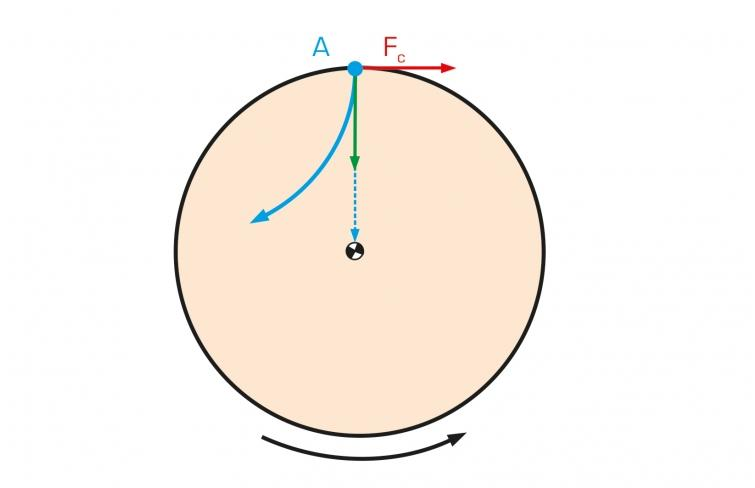

https://www.gunt.de/en/products/engineering-mechanics-and-engineering-design/dynamics/kinetics-dynamics-of-rotation/coriolis-force/040.60500/tm605/glct-1:pa-148:ca-18:pr-1409

 Les forces de Coriolis sont appliquées perpendiculairement à la vitesse du corps en mouvement et sont proportionnelles à la vitesse et la masse de celui-ci. Nous pouvons donc déterminer les forces de Coriolis pour le corps rigide ainsi que pour la masse ajoutée de la façon suivante. 


$${C\left(v\right)=C}_{\textrm{RB}} \left(v\right)+C_A \left(v\right)$$


Nous Pour un corps rigide, les forces de Coriolis peuvent être paramétrisé avec la forme antisymétrique suivante.


$$C_{\textrm{RB}} \left(v\right)=\left\lbrack \begin{array}{cc}
0_{3\times 3}  & -m\;\mathit{\mathbf{S}}\left(v_1 \right)-m\;\mathit{\mathbf{S}}\left(v_1 \right)\mathit{\mathbf{S}}\left(r_G \right)\\
-m\;\mathit{\mathbf{S}}\left(v_1 \right)+m\;\mathit{\mathbf{S}}\left(v_1 \right)\mathit{\mathbf{S}}\left(r_G \right) & -\mathit{\mathbf{S}}\left(Iv_2 \right)
\end{array}\right\rbrack$$


    Où:

        m: masse du sous-marin

        RG: centre de masse.${\mathbb{R}}^{3\times 1}$

        I: tenseur d'inertie ${\mathbb{R}}^{3\times 3}$

        S: matrice anti- symétrique

Nous pouvons développer la matrice, ce qui nous donne la forme suivante.


$$C_{\textrm{RB}} \left(v\right)=\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & m\,{\left({\textrm{RG}}_2 \,q+{\textrm{RG}}_3 \,r\right)} & m\,{\left(w-{\textrm{RG}}_1 \,q\right)} & -m\,{\left(v+{\textrm{RG}}_1 \,r\right)}\\
0 & 0 & 0 & -m\,{\left(w+{\textrm{RG}}_2 \,p\right)} & m\,{\left({\textrm{RG}}_1 \,p+{\textrm{RG}}_3 \,r\right)} & m\,{\left(u-{\textrm{RG}}_2 \,r\right)}\\
0 & 0 & 0 & m\,{\left(v-{\textrm{RG}}_3 \,p\right)} & -m\,{\left(u+{\textrm{RG}}_3 \,q\right)} & m\,{\left({\textrm{RG}}_1 \,p+{\textrm{RG}}_2 \,q\right)}\\
-m\,{\left({\textrm{RG}}_2 \,q+{\textrm{RG}}_3 \,r\right)} & m\,{\left(w+{\textrm{RG}}_2 \,p\right)} & -m\,{\left(v-{\textrm{RG}}_3 \,p\right)} & 0 & I_{3,1} \,p+I_{3,2} \,q+I_{3,3} \,r & -I_{2,1} \,p-I_{2,2} \,q-I_{2,3} \,r\\
-m\,{\left(w-{\textrm{RG}}_1 \,q\right)} & -m\,{\left({\textrm{RG}}_1 \,p+{\textrm{RG}}_3 \,r\right)} & m\,{\left(u+{\textrm{RG}}_3 \,q\right)} & -I_{3,1} \,p-I_{3,2} \,q-I_{3,3} \,r & 0 & I_{1,1} \,p+I_{1,2} \,q+I_{1,3} \,r\\
m\,{\left(v+{\textrm{RG}}_1 \,r\right)} & -m\,{\left(u-{\textrm{RG}}_2 \,r\right)} & -m\,{\left({\textrm{RG}}_1 \,p+{\textrm{RG}}_2 \,q\right)} & I_{2,1} \,p+I_{2,2} \,q+I_{2,3} \,r & -I_{1,1} \,p-I_{1,2} \,q-I_{1,3} \,r & 0
\end{array}\right\rbrack$$


% Corp rigide
    Crb= simplify([zeros(3,3), -m*skew(v1) - m*skew(v2)*skew(RG);
                   -m*skew(v1) + m*skew(RG)*skew(v2), -skew(I*v2)]);

Pour corps rigide qui se déplace dans un fluide idéal, les forces de coriolis hydrodinamqiue peuvent être paramétrisé avec la forme anti-symétrique suivante.


$$C_A \left(v\right)=\left\lbrack \begin{array}{cc}
0_{3\times 3}  & -\mathit{\mathbf{S}}\left(A_{11} v_1 +A_{11} v_2 \right)\\
-\mathit{\mathbf{S}}\left(A_{11} v_1 +A_{11} v_2 \right) & -\mathit{\mathbf{S}}\left(A_{21} v_1 +A_{22} v_2 \right)
\end{array}\right\rbrack$$


    Où:

        $A_{\textrm{ij}}$: Sous matrice de la masse ajouté

        S: matrice anti- symétrique

Nous pouvons développer la matrice, ce qui nous donne la forme suivante.


$$C_A \left(v\right)=\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 0 & -Z_{\dot{w} } \,w & Y_{\dot{v} } \,v\\
0 & 0 & 0 & Z_{\dot{w} } \,w & 0 & -X_{\dot{u} } \,u\\
0 & 0 & 0 & -Y_{\dot{v} } \,v & X_{\dot{u} } \,u & 0\\
0 & -Z_{\dot{w} } \,w & Y_{\dot{v} } \,v & 0 & -N_{\dot{r} } \,r & M_{\dot{q} } \,q\\
Z_{\dot{w} } \,w & 0 & -X_{\dot{u} } \,u & N_{\dot{r} } \,r & 0 & -K_{\dot{p} } \,p\\
-Y_{\dot{v} } \,v & X_{\dot{u} } \,u & 0 & -M_{\dot{q} } \,q & K_{\dot{p} } \,p & 0
\end{array}\right\rbrack$$


% Masse ajouté
Ca =[zeros(3,3), -skew(A11*v1+A12*v2);
     -skew(A11*v1+A12*v2), -skew(A21*v1+A22*v2)];
 
C = Crb + Ca;

### Matrice de d'amortissement

Dans cette section, nous allons construire la matrice qui représente l'amortissement qu'applique l'eau sur le sous-marin. De la même façon que pour la masse ajoutée, nous pouvons négliger les effets de couplage sur les effets hydrodynamique, car nous allons à basse vitesse et que nous pouvons assumer que notre sous-marin a trois plans de symétrie. Aussi, dans le livre *Guidance and Control of Ocean Vehicules *(section 2.4.2 p.43) Thor I. Fossen (1994) explique que tous les termes de degré supérieur à 2 sont négligeables. Il explique aussi que les forces d'amortissement peuvent être superposées en terme quadratique et linéaire. La matrice D peut être définie de la fonction suivante: 


$$D\left(n\right)=D_l \left(v\right)+D_q \left(v\right)$$


    Où:

        $D_l$: la matrice des termes linéaire.

        $D_q$: la matrice des termes quadratique.

La matrice des terme linéaire peuvent être écrite de la façon suivante.


$$D_l \left(v\right)=$$

$$\left\lbrack \begin{array}{cccccc}
X_u  & 0 & 0 & 0 & 0 & 0\\
0 & Y_v  & 0 & 0 & 0 & 0\\
0 & 0 & Z_w  & 0 & 0 & 0\\
0 & 0 & 0 & K_p  & 0 & 0\\
0 & 0 & 0 & 0 & M_q  & 0\\
0 & 0 & 0 & 0 & 0 & X_r 
\end{array}\right\rbrack$$


% Matrice linear damping.
    Dl = diag(CD_L);

La matrice des terme quadratique peut être écrit de la façon suivante.


$$D_q =\left\lbrack \begin{array}{cccccc}
X_{u\left|u\right|} \left|u\right| & 0 & 0 & 0 & 0 & 0\\
0 & Y_{v\left|v\right|} \left|v\right| & 0 & 0 & 0 & 0\\
0 & 0 & Z_{w\left|w\right|} \left|w\right| & 0 & 0 & 0\\
0 & 0 & 0 & K_{p\left|p\right|} \left|p\right| & 0 & 0\\
0 & 0 & 0 & 0 & M_{q\left|q\right|} \left|q\right| & 0\\
0 & 0 & 0 & 0 & 0 & X_{r\left|r\right|} \left|r\right|
\end{array}\right\rbrack$$


Nous pouvons déterminer les terme quadratique vec les équations suivantes


$$X_{u\left|u\right|} =\frac{1}{2}\rho C_D A$$


    Où:

        $\rho$: Densité de l'eau

        $C_D$: constante d'amortissement (drag)

        A ; Aire transversalle

Nous allons déterminer les constantes d'amortissement dans une prochaine section. 

% Equation quadratique de damping
    xu = CD_Q1 * abs(u);
    yv = CD_Q2 * abs(v);
    zw = CD_Q3 * abs(w);
    kp = CD_Q4 * abs(p);
    mq = CD_Q5 * abs(q);
    nr = CD_Q6 * abs(r);

% Matrice quadratic damping.
    Dq = diag([xu yv zw kp mq nr]);

% Matrice de damping.
    D = (Dl + Dq);

### Matrice de gravité 

Dans cette section, nous allons définir le vecteur de flottabilité. Les deux forces sont appliquées sur le sous-marin soit la force gravitationnelle au centre de masse Rg ainsi que la poussée d’Archimède au centre de flottaison Rb.  Ces deux forces s'opposent sur l'axe des Z pour qu'un objet soit en mesure de flotter, il faut que sa masse soit plus faible que la masse d'eau qu'il déplace. Selon SNAME (1950) nous pouvons définir les deux forces sous la forme vectorielle suivante. 


$$W=\left\lbrack \begin{array}{c}
0\\
0\;\\
\textrm{mg}
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;B=\left\lbrack \begin{array}{c}
0\\
0\\
g\rho \nabla 
\end{array}\right\rbrack$$


    Où:

        m: la masse du sous-marin.

        g: la constante gravitationnelle.

*        ρ*: densité de l'eau.

        ∇: volume submergé

Étant donné que notre sous-marin est toujours submergé, nous pouvons que le volume submerger est constant.

% Vecteur gravité
    W = [0; 0; (m * g)];

% Vecteur poussée d'Archimède
    B = [0; 0; (rho * g * volume)];

Étant donné que notre sous-marin est toujours submergé, nous pouvons affirmer que le volume submergé est constant. Cependant, ces forces sont décrites dans le référentiel fixe et sont indépendantes au référentiel objet. La prochaine figure représente la force de gravité et la poussée d’Archimède sur le sous-marin en fonction de son orientation. 

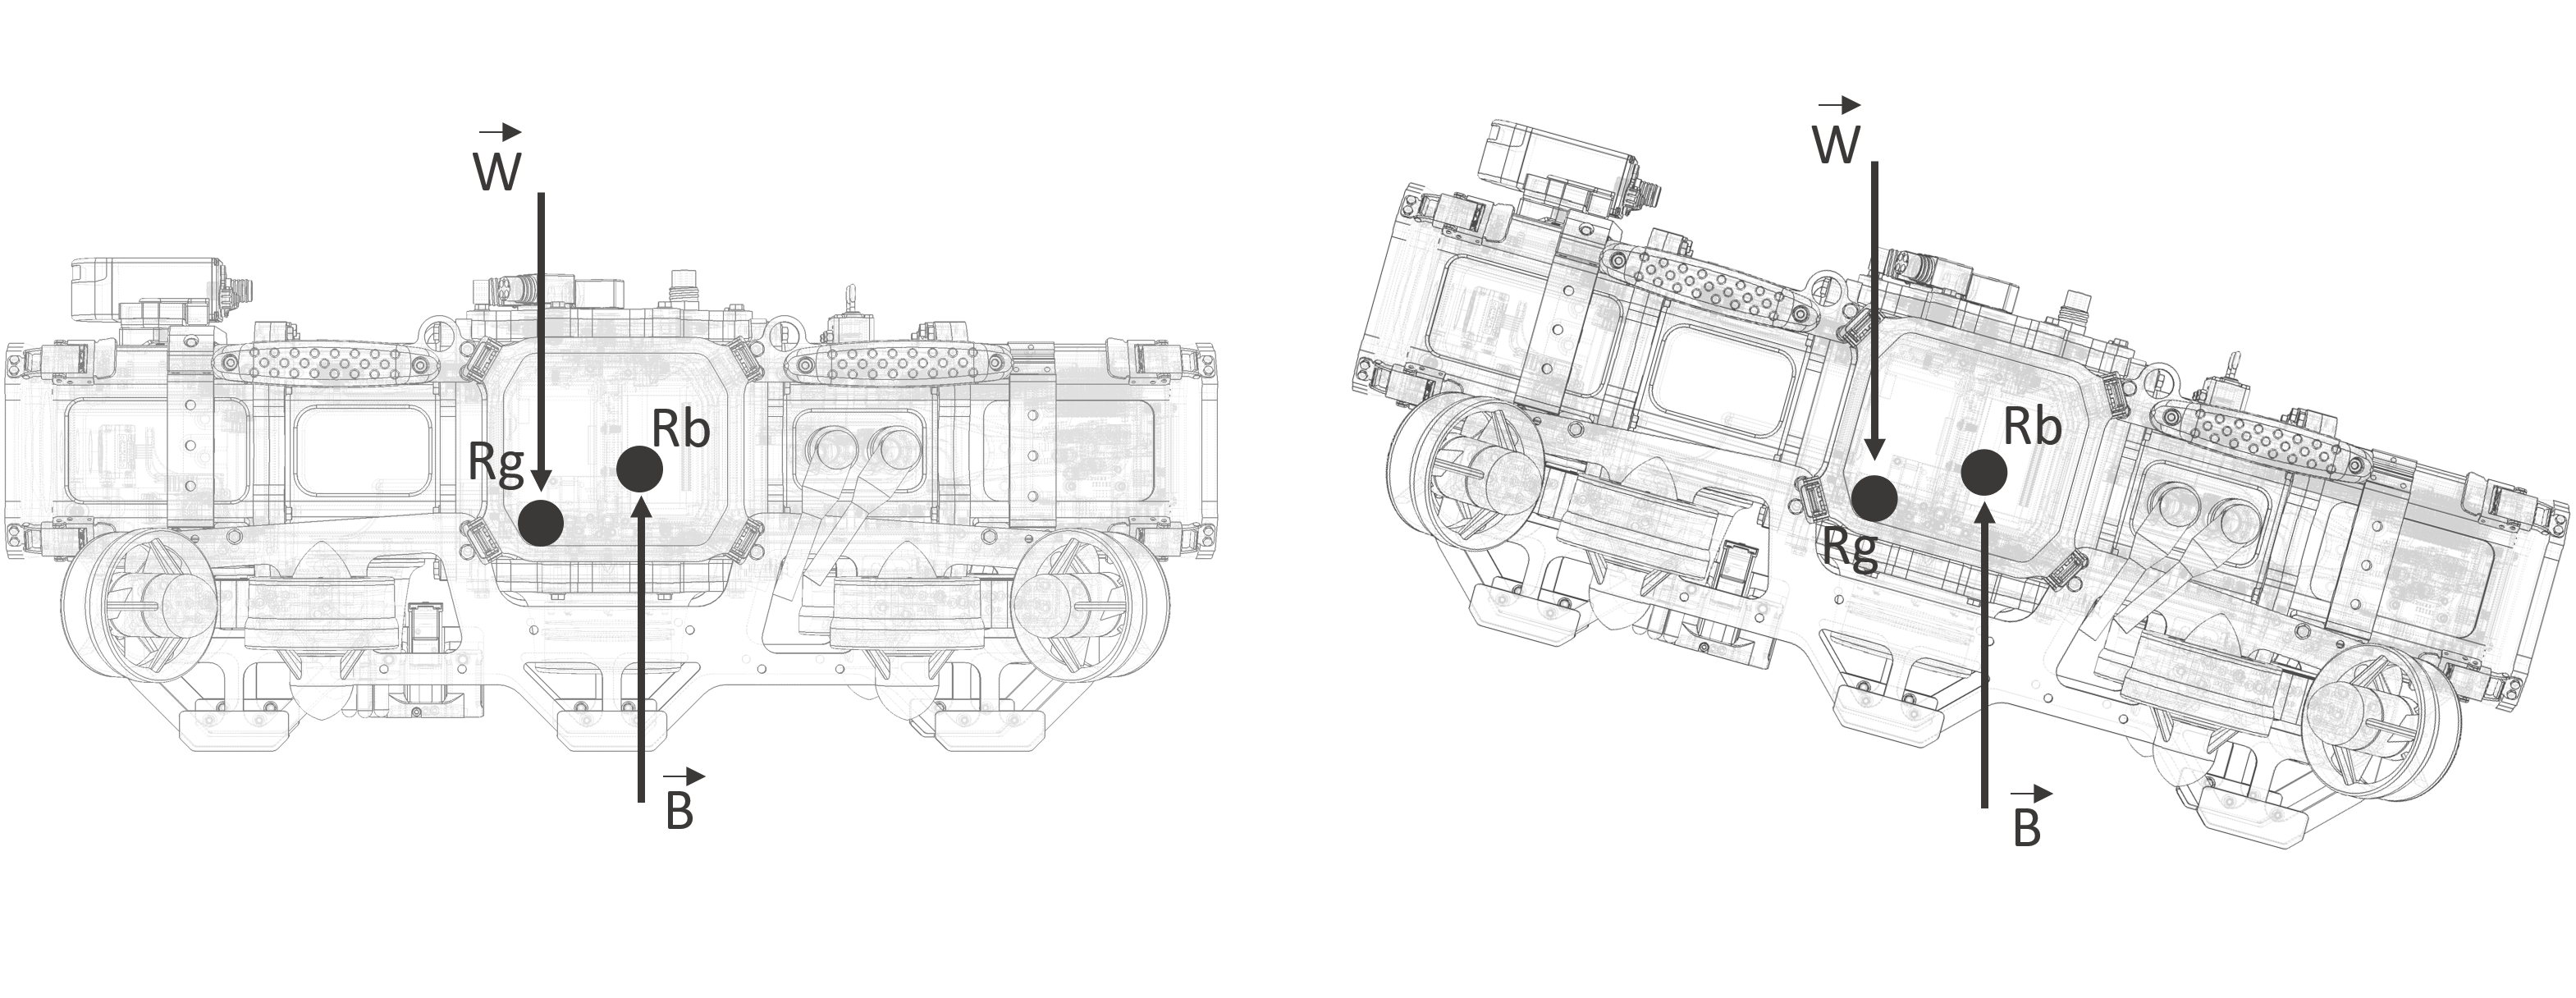

Étant donné que notre équation dynamique est décrite dans le référentiel objet, il faut donc transformer ces forces en utilisant l'orientation du sous-marin. La prochaine figure montre la transformation de ces forces dans le référentiel objet. 

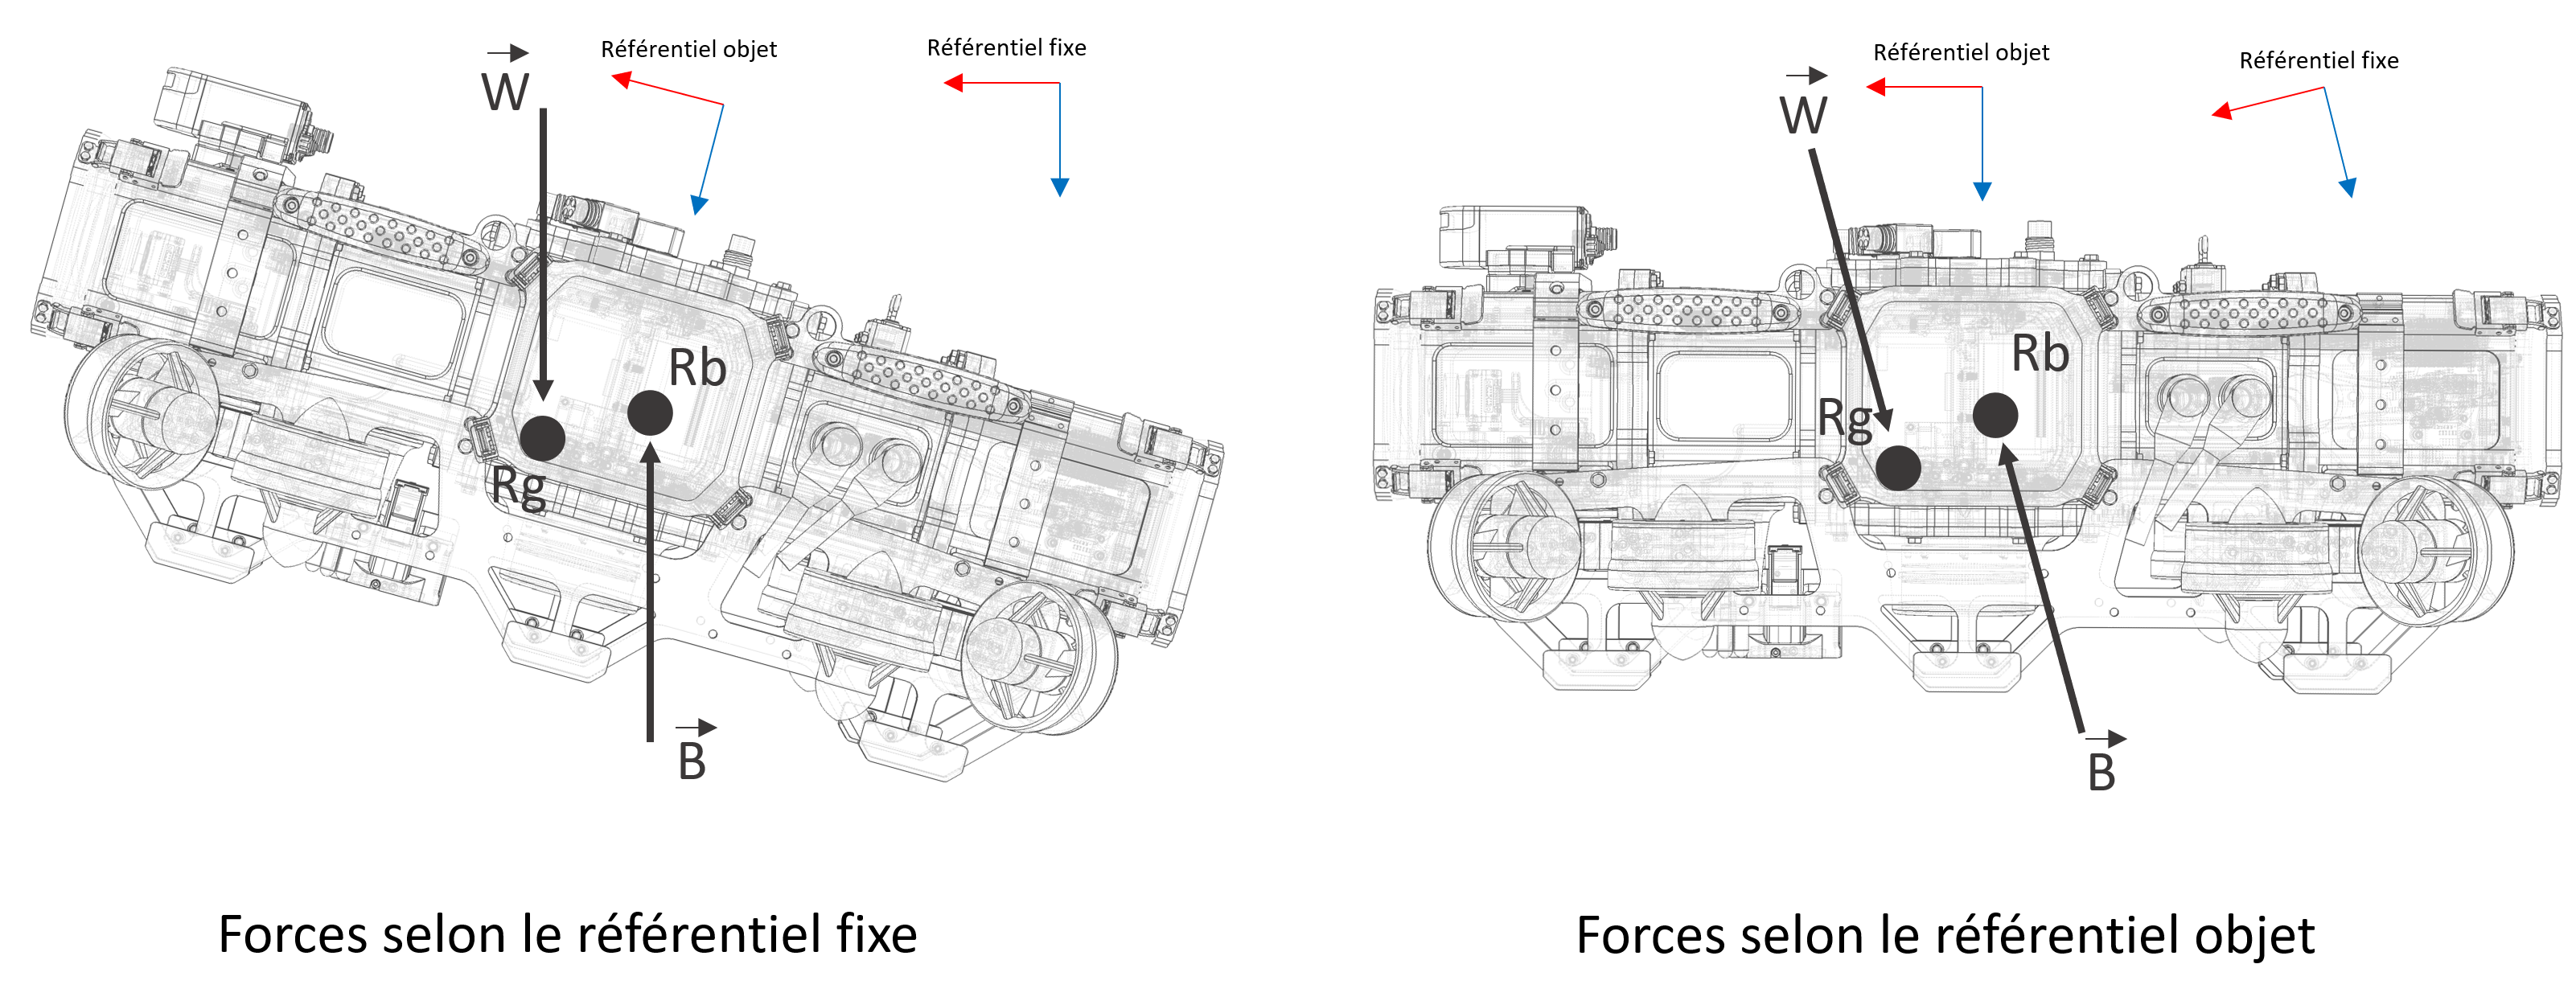

Nous pouvons remarquer que les deux forces ont des composantes selon les trois axes (X Y Z). De plus, vu que les forces ne sont pas appliquées au même point, ceci va aussi créer des moments de force dans les trois axes (Rx Ry Rz). Nous pouvons transformer ces deux forces avec le quaternion décrivant l'orientation du sous-marin avec la relation suivante. Nous pouvons réutiliser la matrice $E_1$que nous avons défini plus tôt. 


$$f_G \left(e\right)=E_1^T \left(e\right)W\;\;\;\;\;\;\;\;\;\;\;f_B =E_1^T \left(e\right)B\;$$


% Vecteur Force selon le quaternion
    FGq = E1.' * W;
    FBq = E1.' * B; 

Nous pouvons aussi transformer ces forces avec la représentation des angles d'Euler avec la relation suivante. 


$$f_G \left(n_2 \right)=J_1^T \left(n_2 \right)W\;\;\;\;\;\;\;\;\;\;\;f_B \left(n_2 \right)=J_1^T \left(n_2 \right)B$$


% Vecteur gravité selon les angles d'Euler
    FGe = J1.' * W;
    FBe = J1.' * B;

Nous pouvons donc écrire l'équation d'équilibre en 6 dégré de liberté qui prend la forme suivante. Ici, Rg peut dépendre du quaternion ou des angle d'Euler.


$$g_{\left(n\right)} =\left\lbrack \begin{array}{c}
{\;f_B -f}_G \\
r_B \times \;f_B -r_G \times \;f_G \;
\end{array}\right\rbrack$$


Nous pouvons dévelloper cette équation avec la représentation basé sur le quaternion. Ceci donne la forme suivante.


$$g\left(n_q \right)=\left\lbrack \begin{array}{c}
-2\,g\,{\left(\textrm{mass}-\rho \,\textrm{volume}\right)}\,{\left(\varepsilon_1 \,\varepsilon_3 -\varepsilon_2 \,\eta \right)}\\
-2\,g\,{\left(\textrm{mass}-\rho \,\textrm{volume}\right)}\,{\left(\varepsilon_2 \,\varepsilon_3 +\varepsilon_1 \,\eta \right)}\\
g\,{\left(\textrm{mass}-\rho \,\textrm{volume}\right)}\,{\left(2\,{\varepsilon_1 }^2 +2\,{\varepsilon_2 }^2 -1\right)}\\
{\textrm{RG}}_2 \,g\,\textrm{mass}\,{\left(2\,{\varepsilon_1 }^2 +2\,{\varepsilon_2 }^2 -1\right)}+{\textrm{RG}}_3 \,g\,\textrm{mass}\,{\left(2\,\varepsilon_2 \,\varepsilon_3 +2\,\varepsilon_1 \,\eta \right)}-{\textrm{RB}}_2 \,g\,\rho \,\textrm{volume}\,{\left(2\,{\varepsilon_1 }^2 +2\,{\varepsilon_2 }^2 -1\right)}-{\textrm{RB}}_3 \,g\,\rho \,\textrm{volume}\,{\left(2\,\varepsilon_2 \,\varepsilon_3 +2\,\varepsilon_1 \,\eta \right)}\\
{\textrm{RB}}_1 \,g\,\rho \,\textrm{volume}\,{\left(2\,{\varepsilon_1 }^2 +2\,{\varepsilon_2 }^2 -1\right)}-{\textrm{RG}}_3 \,g\,\textrm{mass}\,{\left(2\,\varepsilon_1 \,\varepsilon_3 -2\,\varepsilon_2 \,\eta \right)}-{\textrm{RG}}_1 \,g\,\textrm{mass}\,{\left(2\,{\varepsilon_1 }^2 +2\,{\varepsilon_2 }^2 -1\right)}+{\textrm{RB}}_3 \,g\,\rho \,\textrm{volume}\,{\left(2\,\varepsilon_1 \,\varepsilon_3 -2\,\varepsilon_2 \,\eta \right)}\\
{\textrm{RG}}_2 \,g\,\textrm{mass}\,{\left(2\,\varepsilon_1 \,\varepsilon_3 -2\,\varepsilon_2 \,\eta \right)}-{\textrm{RG}}_1 \,g\,\textrm{mass}\,{\left(2\,\varepsilon_2 \,\varepsilon_3 +2\,\varepsilon_1 \,\eta \right)}+{\textrm{RB}}_1 \,g\,\rho \,\textrm{volume}\,{\left(2\,\varepsilon_2 \,\varepsilon_3 +2\,\varepsilon_1 \,\eta \right)}-{\textrm{RB}}_2 \,g\,\rho \,\textrm{volume}\,{\left(2\,\varepsilon_1 \,\varepsilon_3 -2\,\varepsilon_2 \,\eta \right)}
\end{array}\right\rbrack$$


Il est important de noté que matlab ne simplifie pas de la même façon que certain livre, mais ce sont des équations équivalente.

% Vecteur gravité pour le controlleur selon le quaternion
    Gq = simplify([FBq - FGq;
                   cross(RB, FBq) - cross(RG, FGq)]);

Nous pouvons développer cette équation avec la représentation basé sur les angles d'Euler. Ceci donne la forme suivante.


$$g\left(n_e \right)=\left\lbrack \begin{array}{c}
g\,\sin \left(\theta \right)\,{\left(m-\rho \,\textrm{volume}\right)}\\
-g\,\cos \left(\theta \right)\,\sin \left(\phi \right)\,{\left(m-\rho \,\textrm{volume}\right)}\\
-g\,\cos \left(\phi \right)\,\cos \left(\theta \right)\,{\left(m-\rho \,\textrm{volume}\right)}\\
g\,\cos \left(\theta \right)\,{\left({\textrm{RG}}_3 \,m\,\sin \left(\phi \right)-{\textrm{RG}}_2 \,m\,\cos \left(\phi \right)+{\textrm{RB}}_2 \,\rho \,\textrm{volume}\,\cos \left(\phi \right)-{\textrm{RB}}_3 \,\rho \,\textrm{volume}\,\sin \left(\phi \right)\right)}\\
g\,{\left({\textrm{RG}}_3 \,m\,\sin \left(\theta \right)-{\textrm{RB}}_3 \,\rho \,\textrm{volume}\,\sin \left(\theta \right)+{\textrm{RG}}_1 \,m\,\cos \left(\phi \right)\,\cos \left(\theta \right)-{\textrm{RB}}_1 \,\rho \,\textrm{volume}\,\cos \left(\phi \right)\,\cos \left(\theta \right)\right)}\\
-g\,{\left({\textrm{RG}}_2 \,m\,\sin \left(\theta \right)-{\textrm{RB}}_2 \,\rho \,\textrm{volume}\,\sin \left(\theta \right)+{\textrm{RG}}_1 \,m\,\cos \left(\theta \right)\,\sin \left(\phi \right)-{\textrm{RB}}_1 \,\rho \,\textrm{volume}\,\cos \left(\theta \right)\,\sin \left(\phi \right)\right)}
\end{array}\right\rbrack$$


Il est important de noté que matlab ne simplifie pas de la même façon que certain livre, mais ce sont des équations équivalente.

% Vecteur gravité pour le controlleur selon les angles d'Euler    
    Ge  = simplify([FBe - FGe;
                    cross(RB, FBe) - cross(RG, FGe)]);

Étant donné que nous supposons que le volume submergé est constant et que notre sous-marin flotte, l'équation que nous venons de définir va toujours vouloir faire monter le sous-marin. En boucle ouverte, cela signifie que le sous-marin va toujours vouloir remonter à la surface et même sortir de l’eau. Cela n'est pas désirable pour le modèle physique de notre simulateur. Cependant, calculer le volume submergé en fonction de la profondeur peut être une tâche compliquée et dans notre cas, nous voulons juste une approximation simple pour que le sous-marin ne sorte pas de l'eau en simulation. Nous avons décidé d'utiliser une équation d'erreur gaussienne, car elle possède deux asymptotes horizontales. Cette équation a la forme suivante.

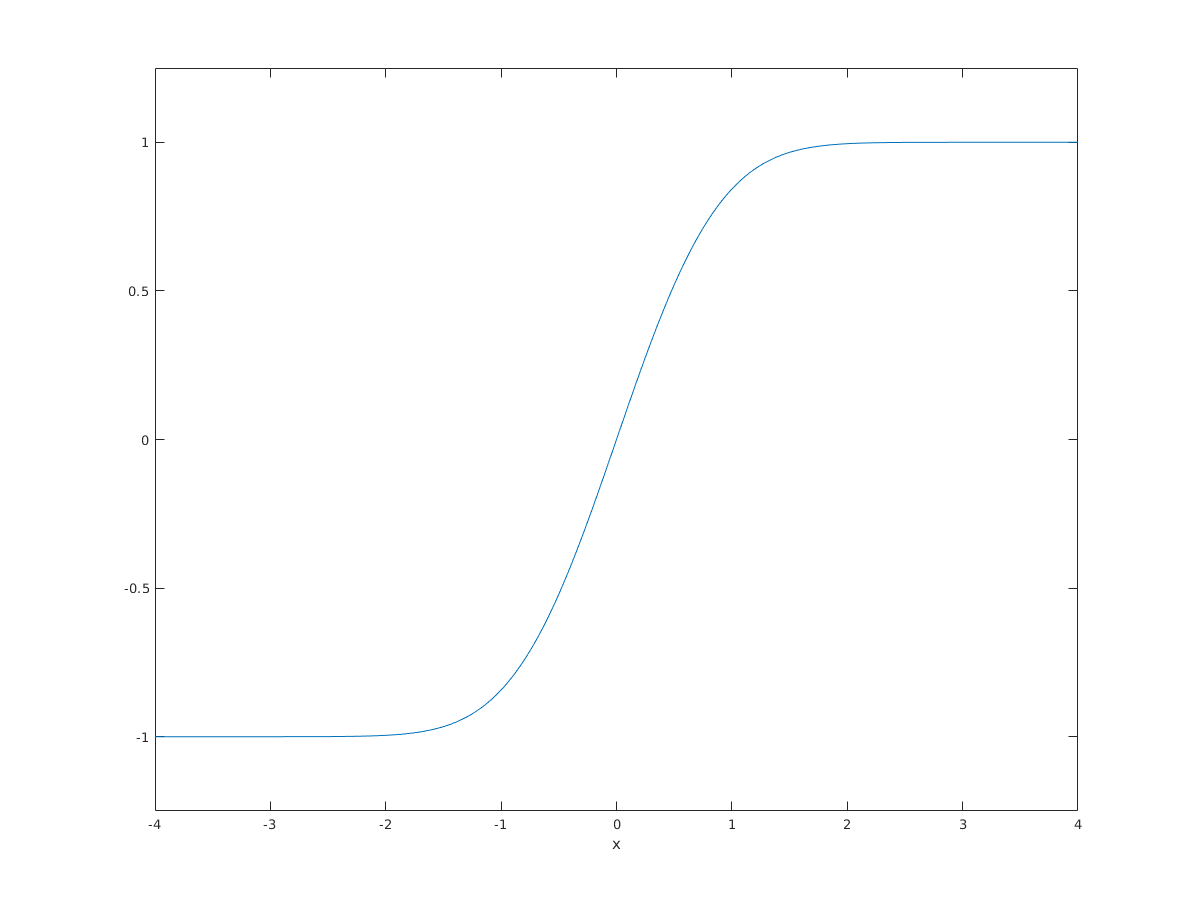

Nous pouvons donc paramétrer cette équation afin d'avoir un volume submergé nul quand $z\le 0$ et d'avoir notre volume submergé quand z = la hauteur du sous-marin. L'équation peut prendre la forme canonique suivante. 


$$\nabla \left(z\right)=a\;\textrm{erf}\left(b\left(z-h\right)\right)+k$$



$$\nabla \left(z\right)=\frac{\nabla }{2}\textrm{erf}\left(\frac{4}{H}\left(z-\frac{H}{2}\right)\right)+\frac{\nabla }{2}$$


    Où: 

        H : la hauteur du sous-marin 

Par la suite, nous pouvons remplacer le volume submergé $\nabla$par par la relation$\nabla \left(z\right)$dans le vecteur de flotabilité. Ceci apporte de bon résultat dans le simulateur, mais on ne recomande pas de s'en servir dans la loi de commande, car cette approximation n'ets pas représentative d'un point de vu physique.

    
% Équation du volume submergé selon la profondeur z.     /͞ ͞
% Équation à double asymptote horizontal. Voir erf()  __/

% Calculs des constantes
     aa= volume/2;   % Calculer l'amplitude.
     kk=aa;          % Monter la courbe pour avoir min 0 et max volume.
     bb=4/H;         % Calculer la pente transitoire.
     hh=H/2;         % Décaler la courbe pour avoir x(0)=0. 

% Équation erf
    vz=aa*erf(bb*(z-hh))+kk;
    
% Vecteur gravité pour simulation selon le quaternion
    Gqb = subs(Gq,volume,vz);
    Geb = subs(Ge,volume,vz);


### Matrice de moteurs

Dans cette section, nous allons définir le vecteur *τ* qui représente la force résultante de la commande pour chaque degré de liberté. Dans notre cas, il s'agit de la somme des forces et moments de tous les moteurs présents sur le sous-marin. Étant donné que l'orientation des moteurs est fixe, nous pouvons nous faire une faveur et déjà représenter le vecteur *τ* sous la représentation d'état linéaire suivant. 

### 
$$\tau =\textrm{Bu}$$


    Où: 

        B: est la matrice de commande ${\mathbb{R}}^{6\textrm{xm}}$

        u: vecteur de la commande ${\mathbb{R}}^{\textrm{mx1}}$

        m: le nombre de moteur

Étant donné que cette matrice B ne sera pas notre véritable matrice de commande de notre système, nous allons la définir $T_M \;$afin d'éviter des confusions dans la section d'analyse. Nous pouvons définir l'orientation de la force du moteur selon le référentiel suivant. 

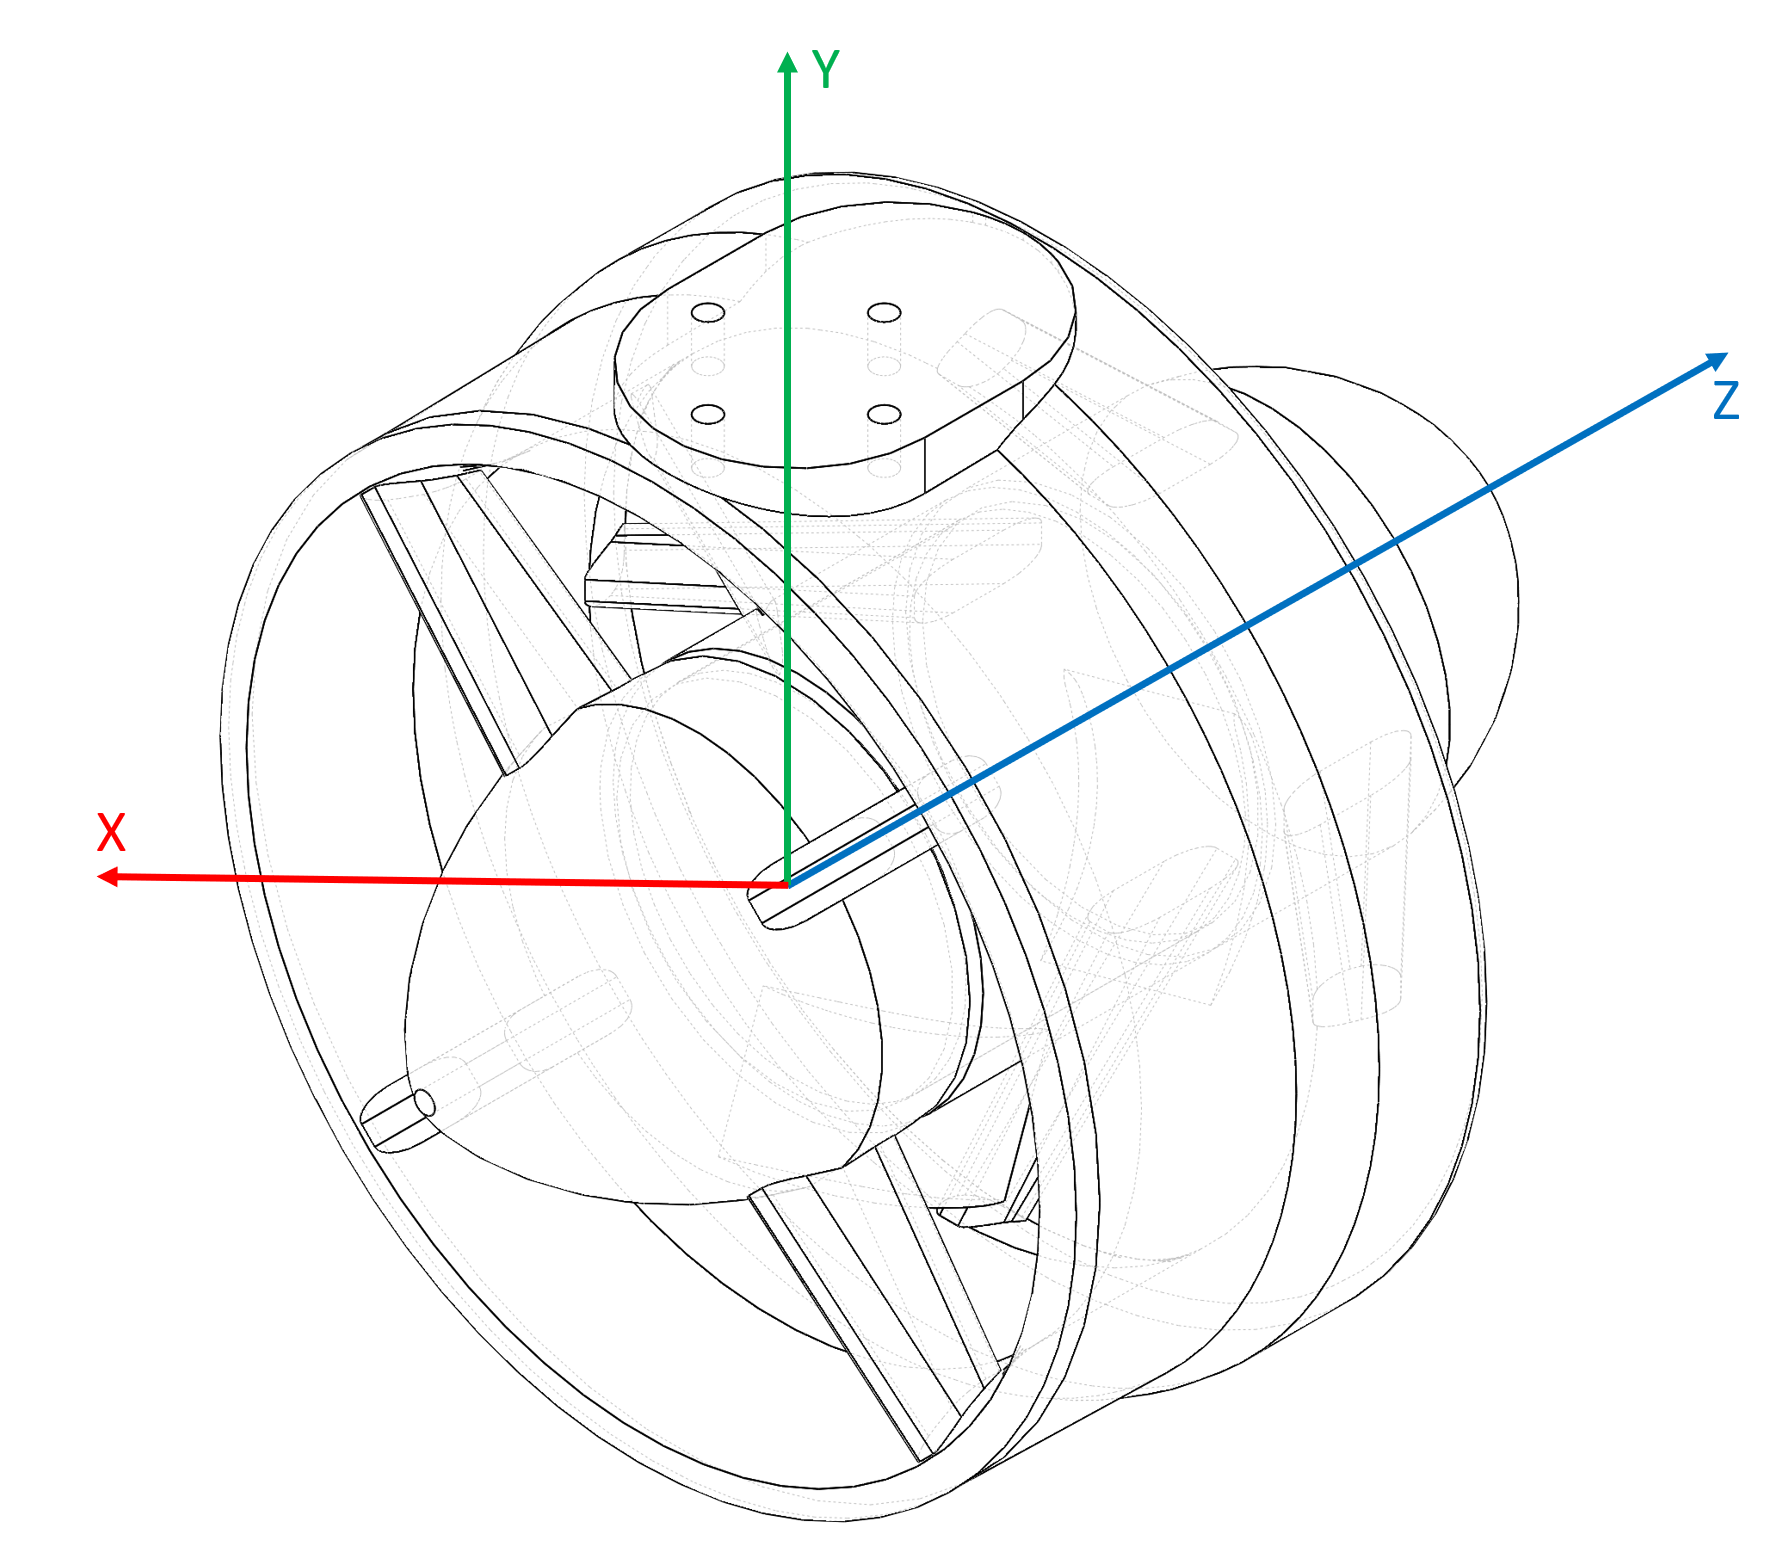

Dans le cas où l'hélice horaire est installée sur le moteur, nous pouvons définir l'orientation du vecteur force par rapport au moteur de la façon suivante:


$$o_T =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$$


Dans le cas où l'hélice antihoraire est installée, il faut inverser l'orientation du moteur. Cependant, ce qui nous intéresse dans la matrice de commande, c'est la réaction des moteurs sur le sous-marin et non la force de poussée du moteur. La figure suivante montre la différence entre les deux. 

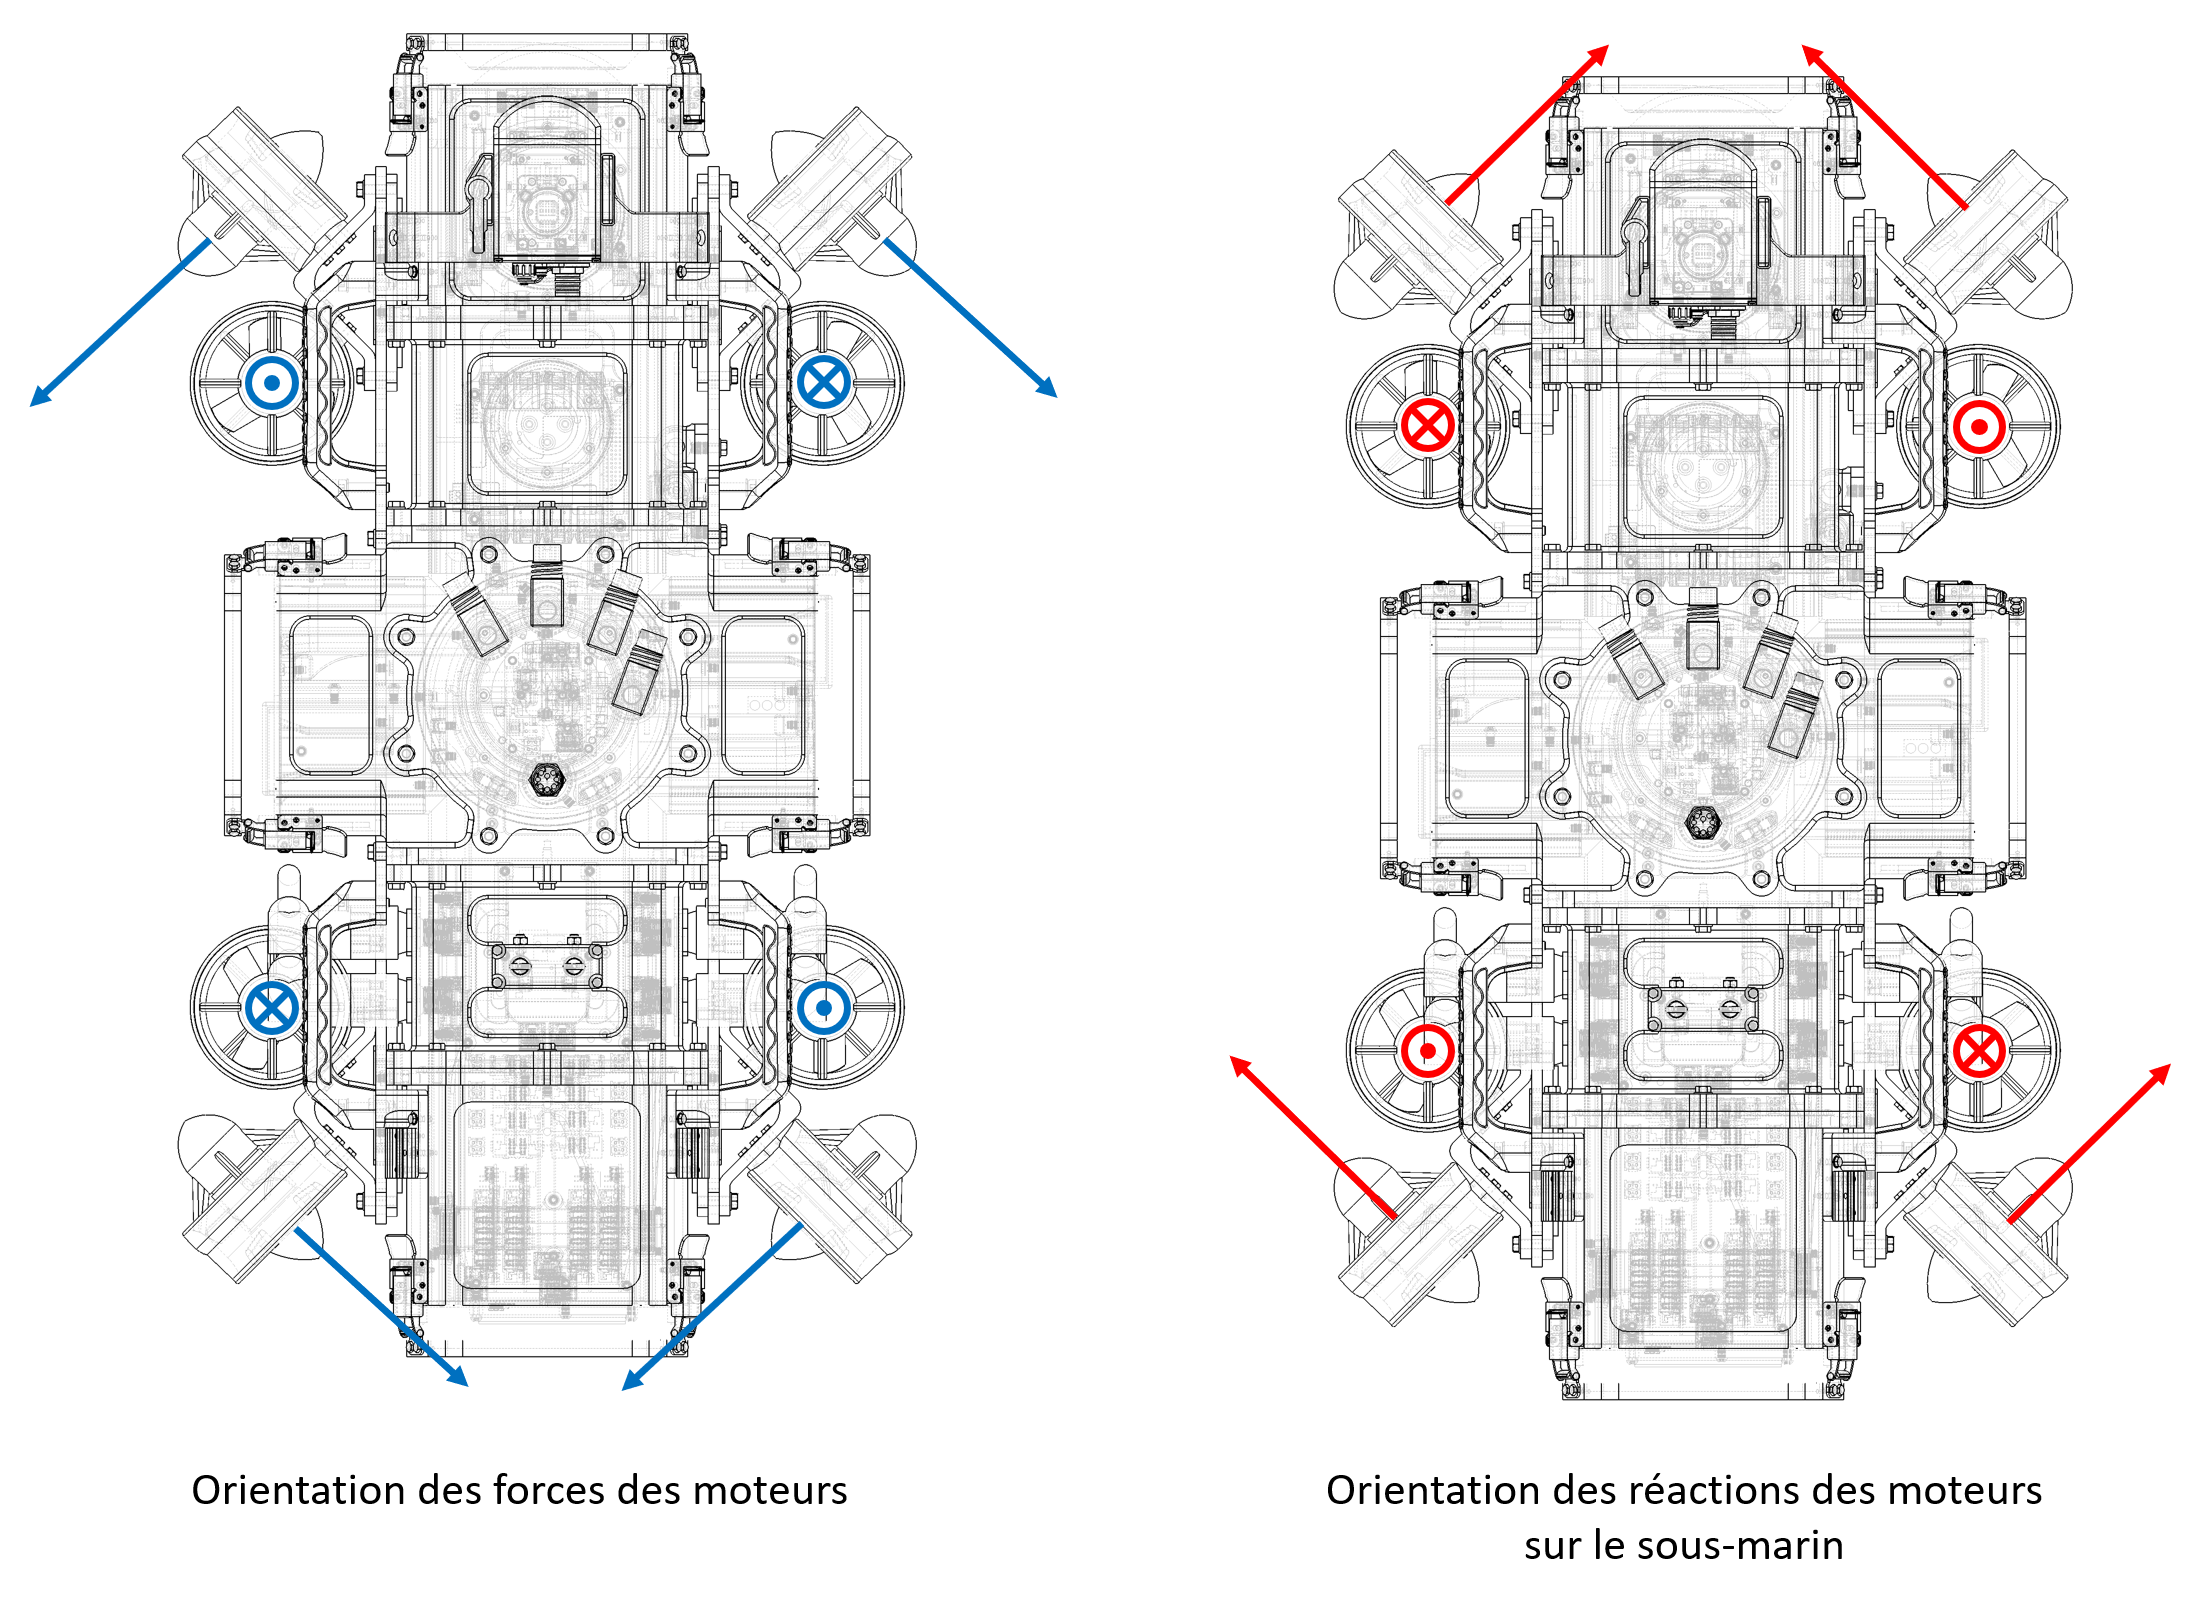

Nous savons que la réaction du moteur sur le sous-marin est inverse à la force de poussée. Nous pouvons donc définir l'orientation du vecteur réaction par rapport au moteur de la façon suivante : 


$$o_R =\left\lbrack \begin{array}{c}
0\\
0\\
-1
\end{array}\right\rbrack$$


% Définition du vecteur or
    or=[0;0;-1];   

Comme pour le vecteur gravité, nous pouvons orienter le vecteur réaction en fonction d'un quaternion qui représente l'orientation du moteur selon le référentiel objet. Nous pouvons utiliser la relation suivante.


$$r_t \left(e\right)=E_1 \left(e\right)o_R$$


    Où:

        $E_1$: La matrice de transformation de l'orientation du moteur par rapport référentiel objet ${\mathbb{R}}^{3\textrm{x3}}$.

% définition du vecteur rt  
    rt=E1*or;

Nous pouvons donc écrire la contribution de chaque moteur pour les 6 degrés de libertés avec la relation suivante.


$$T=\left\lbrack \begin{array}{c}
r_t \left(e\right)\\
d_t \times r_t \left(e\right)\;\;
\end{array}\right\rbrack$$


    Où:

        $d_t$: la distance entre le moteur et le centre de masse${\;r}_G$ ${\mathbb{R}}^3$.

        Nous pouvons développer le vecteur T. ceci donne:


$$T=\left\lbrack \begin{array}{c}
-2\,\varepsilon_1 \,\varepsilon_3 -2\,\varepsilon_2 \,\eta \\
2\,\varepsilon_1 \,\eta -2\,\varepsilon_2 \,\varepsilon_3 \\
2\,{\varepsilon_1 }^2 +2\,{\varepsilon_2 }^2 -1\\
d_{\textrm{T2}} \,{\left(2\,{\varepsilon_1 }^2 +2\,{\varepsilon_2 }^2 -1\right)}+d_{\textrm{T3}} \,{\left(2\,\varepsilon_2 \,\varepsilon_3 -2\,\varepsilon_1 \,\eta \right)}\\
-d_{\textrm{T1}} \,{\left(2\,{\varepsilon_1 }^2 +2\,{\varepsilon_2 }^2 -1\right)}-d_{\textrm{T3}} \,{\left(2\,\varepsilon_1 \,\varepsilon_3 +2\,\varepsilon_2 \,\eta \right)}\\
d_{\textrm{T2}} \,{\left(2\,\varepsilon_1 \,\varepsilon_3 +2\,\varepsilon_2 \,\eta \right)}-d_{\textrm{T1}} \,{\left(2\,\varepsilon_2 \,\varepsilon_3 -2\,\varepsilon_1 \,\eta \right)}
\end{array}\right\rbrack$$


% Definir du vecteur thruster
    Tt=[rt;cross(d_T-RG,rt)]; % Fossen(2021) eq9.67 page 233

Étant donné que la matrice de commande a un nombre de colonnes égales au nombre de moteurs. Nous pouvons répéter le vecteur T pour chaque moteur.


$${{B=\forall }_i \in m\;:\;T}_i =\left\lbrack \begin{array}{c}
r_t \left(e_i \right)\\
d_{t\left(i\right)} \times r_t \left(e_i \right)\;\;
\end{array}\right\rbrack$$


    Où

        m: le nombre de moteur.

        i: index du moteur.

 
% Crée la matrice Thrusters 

    Tm=zeros(6,size(physics.thruster.T,1));   
    
    for i=1:size(physics.thruster.T,1)
        
       qt= eul2quat(deg2rad(physics.thruster.T(i,4:6)),'ZYX');           % convertir les angle d'euler en uaternion
       Tm(:,i)=subs(Tt,[e;d_T;RG],[qt,physics.thruster.T(i,1:3),physics.RG].');  % Calculer le vecteur thrusters
    end
   Tm
    

Nous pouvons définir le vecteur de commande u pour nos  moteurs.

## 
$$u={\left\lbrack U_1 \;U_2 \;\ldotp \ldotp \ldotp U_m \right\rbrack }^T$$


        
% Définir les entrées système (Thruster)
    syms ('U',[size(physics.thruster.T,1),1]);

### Perturbations

Les forces de perturbations sont des forces externes au système sur lequel nous n’avons pas de contrôle et qui sont imprévisibles. La modélisation des perturbations permet de bien évaluer la robustesse du contrôleur. En raison du contexte actuel, nous ne pouvons pas aller faire des tests expérimentaux en piscine. Nous voulons donc que notre modèle soit le plus fiable possible afin d'éviter des surprises non désirables lorsqu’on va pouvoir retourner à l’eau. Nous aimerions modéliser les perturbations en utilisant le spectre de Pierson-Moskowitz comme présenté dans le livre *Guidance and Control of* *Ocean* *Véhicules* (section 2.3.1 p.63) Thor I. Fossen (1994). Cependant, par contrainte de temps, nous allons appliquer cette méthode ultérieurement. Pour l’instant, nous avons utilisé des fonctions sinus avec des amplitudes et des fréquences aléatoires pour modéliser les forces des vagues sur les 6 dégrées de liberté. Aussi, nous avons utilisé des fonctions de nombre aléatoire qui sont saturés en fonction des paramètres min et max aussi définit de façon aléatoire pour modéliser les forces de dérive sur les axes x et y. Nous avons linéairement superposé ces deux forces pour créer notre vecteur de perturbation $\tau_E$. En boucle ouverte avec une commande nulle, il est désormais impossible de prédire la position et l’orientation du sous-marin. La figure suivante montre la réponse en boucle ouverte pour deux simulations. 

## Équation différentiel non linéaire

Maintenant que nous avons déterminer tous les termes des équations différentiels, Nous pouvons regrouper l'équation dynamique et cinématique afin d'obtenir toute les équations diférentiels pour décirir le comportement d'un sous-marin en 6 degrées de liberté. Nous allons utiliser la représentation d'états pour représenter ces équations différentiel. La forme générale de la représentation d'état peut s'écrire de la façon suivante


$$\dot{x} \left(t\right)=f\left(x\left(t\right),\;u\left(t\right)\right)$$


    Où:

    $x$: Le vecteur des états du système.

    $\dot{x}$: Le vecteur des dérivés des états du système.

    $u$: Le vecteur de commande.

Dans les prochaines sous sections, nous allons définir le modèle d'états du sous-marin avec la représentation basé sur les quaternion et ainsi que sur les angles d'Euler.

### Équation différentiel avec la représentation basé sur les quaternions

Pour le modèle avec la représentation basé sur les quaternions, nous pouvons définir les variables d'états du système comme suit:


$$x_q ={\left\lbrack {n_q }^T \;v^T \right\rbrack }^T ={\left\lbrack x\;y\;z\;\eta \;\varepsilon_1 \;\varepsilon_2 \;\varepsilon_3 u\;v\;w\;p\;q\;r\;\right\rbrack }^T$$


Avec cette représentation , notre système possède 13 états et conscéquament 13 équation différentielles. Nous pouvons écrire le modèle d'état comme suit:


$$\left\lbrack \begin{array}{c}
{\dot{n} }_q \\
\dot{v} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
E\left(e\right)\;v\\
M^{-1} \left\lbrack -C\left(v\right)v-D\left(v\right)v-g\left(n_q \right)+B\;u\right\rbrack 
\end{array}\right\rbrack$$


% Inverser la matrice M
    Minv=inv(M);

% Équation non linéaire (Quaternion) pour le controlleur sans perturbation.
    simq(1:7) = E*V;
    simq(8:13) = Minv*(-C*V - D*V - Gq +Tm*U);

% Équation non linéaire (Quaternion) sans moteur pour le controlleur mpc.
    simqa(1:7) = E*V;
    simqa(8:13) = Minv*(-C*V - D*V - Gq);


Nous pouvons aussi définir un deuxième modèle d'états pour notre simulateur ou on ajoute les perturbation ainsi que le vecteur gravité borné.


$$\left\lbrack \begin{array}{c}
{\dot{n} }_q \\
\dot{v} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
E\left(e\right)\;v\\
M^{-1} \left\lbrack -C\left(v\right)v-D\left(v\right)v-g_b \left(n_q \right)+\tau_E +B\;u\right\rbrack 
\end{array}\right\rbrack$$


% Équation non linéaire (Quaternion) pour la simulation avec perturbation.
      simqp(1:7) = E*V;
      simqp(8:13) = Minv*(-C*V - D*V - Gqb + Tm*U + F_ext)  ;% Vérifié par Charles

% Équation non linéaire (Quaternion) pour la simulation avec perturbation sans moteur.
      simqpa(1:7) = E*V;
      simqpa(8:13) = Minv*(-C*V - D*V - Gqb + F_ext)  ;% Vérifié par Charles
       

### Équation différentiel avec la représentation basé sur les angles d'Euler

Pour le modèle avec la représentation basé sur les angles d'Euler, nous pouvons définir les variables d'états du système comme suit:


$$x_e ={\left\lbrack {n_e }^T \;v^T \right\rbrack }^T ={\left\lbrack x\;y\;z\;\;\phi \;\theta \;\psi \;u\;v\;w\;p\;q\;r\;\right\rbrack }^T$$


Avec cette représentation , notre système possède 12 états et conscéquament 12 équation différentielles. Nous pouvons écrire le modèle d'état comme suit:


$$\left\lbrack \begin{array}{c}
{\dot{n} }_e \\
\dot{v} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
J\left(n_2 \right)\;v\\
M^{-1} \left\lbrack -C\left(v\right)v-D\left(v\right)v-g\left(n_e \right)+B\;u\right\rbrack 
\end{array}\right\rbrack$$


% Équation non linéaire (Euler) pour simulation avec perturbation
     sime(1:6) = J*V;
     sime(7:12) = Minv*(-C*V - D*V - Ge + Tm*U ); % Vérifié par Charles

### Substituer les constantes du modèle du sous-marin

Dans cette sections, nous allons substituer les valeurs numérique des constante mécanique de notre sous-marin dans les équations différentielles que nous avons défini dans la section précédentes.

%% Chargement des paramètres
    constValues = [
                 physics.mass ...
                 physics.volume ...
                 physics.height...
                 physics.I(1,:) ...
                 physics.I(2,:) ...
                 physics.I(3,:) ...
                 physics.RG ...
                 physics.RB ...
                 physics.CDL...
                 physics.CDQ...
                 physics.AddedMass...
                 physics.rho ...
                 physics.g]; 

             
% Substituer les constantes dans les équation différentielles
    simqpc = subs(simqp, constMec, constValues);
    simqc = subs(simq, constMec, constValues);
    simec = subs(sime, constMec, constValues);
    %simqec = subs(simqe, constMec, constValues);
    %simedc = subs(simed, constMec, constValues);

% Calculer la jacobienne pour le MPC non linéaire    
    Anq = jacobian(simq,[Nq;V]);
    Bnq = jacobian(simq,[U]);
    Cnq = jacobian([Nq;V],[Nq;V]);
    Dnq = jacobian([Nq;V],[U]); 

    %Anq(1:7,1:7)= zeros(7,7);
    E_dot;
    Anqv = subs(Anq, constMec, constValues);
    Bnqv = subs(Bnq, constMec, constValues);

% Calculer la jacobienne pour le EKF procNav
    Anqp = jacobian(simqpc,[Nq;V]);
    Bnqp = jacobian(simqpc,[U]);
    Cnqp = jacobian([Nq;V],[Nq;V]);
    Dnqp = jacobian([Nq;V],[U]); 


## Étude linéaire du système en boucle ouverte

Maintenant que nous avons substitué nos constantes mécaniques, nous allons étudier notre système afin de déterminer sa stabilité, sa contrôlabilité et son observabilité. Afin de vérifier ces critères, selon les méthodes vues dans le cours SYS823, nous devons dans un premier temps linéariser le système, car cette méthode ne fonctionne que sur des modèles linéaires. Pour l'étude du sous-marin, nous n'allons pas utiliser la représentation basée sur le quaternion, car il ne possède pas une représentation généralisée (4 paramètres pour 3 degrés de liberté). 

Pour être en mesure de bien représenter une orientation avec quatre paramètres, le quaternion doit posséder une contrainte afin d'offrir une solution unique. Le quaternion doit donc être unitaire afin de bien décrire une orientation dans l'espace. La contrainte peut être définie de la façon suivante. 


$$e^T e=\eta^2 +\varepsilon_1^2 +\varepsilon_2^2 +\varepsilon_3^2 =1$$


Cependant, lors de la linéarisation du système, cette contrainte disparait et va donc erroné l'étude du système. Il est possible de réduire le quaternion à 3 paramètres en remplaçant la partie scalaire *η* par la contrainte. Ce qui donne: 


$$\eta =\sqrt{{-\varepsilon }_1^2 -\varepsilon_2^2 -\varepsilon_3^2 +1}$$


Cependant, comme toute représentation à 3 paramètres, cela va créer des zones de singularité. Dans le cas du quaternion réduit, les zones de singularité apparaissent lorsque $\eta =0$. Cette représentation n'est pas désirable car elle contient des zone de singularité qui se trouve dans notre plage d'application. Par exemple ($\phi =\theta =0\;\textrm{et}\;\psi =\pm \pi$).

Nous trouvons donc qu'il est plus avantageux de faire l'étude du système basé sur les angles d'Euler, car ses zones de singularité ne se trouvent pas dans notre plage d'application. De plus, cette représentation est plus intuitive. 

### Déterminer les point d'équilibres

Afin que la linéarisation soit pertinente, il faut linéariser le système à un point d'équilibre. Un point d'équilibre est un état du système pour lequel le résultat de toutes les équations différentielles est nul. Cela signifie que le système n'évolue plus. Nous pouvons résoudre les équations différentielles de la façon suivante pour déterminer le ou les points d'équilibres. 


$$0=f\left(x\right)$$


Étant donné que nous étudions le système en boucle ouverte, cela signifie que le vecteur commande doit être constant. Nous pouvons donc assumer que pour toutes les positions x et y, toutes les orientations *ψ* ainsi que pour toutes les positions $z\ge 0$, le système peut être en condition d'équilibre. Ceci est possible, car les variable d'états $x,y,\;\textrm{et}\;\psi$ n'ont pas d'impact sur l'équation dynamique. De plus, cela va nous permettre de nous stabiliser partout dans l'environnement, ce qui est désirable. Nous allons arbitrairement poser le vecteur commande u, la position x et y ainsi que l'orientationn $\psi$ à 0 .

Après analyse numérique nous trouver le point d'équilibre qui représente le sous-marin qui flotte au repos.


$$x_{\textrm{ss}} =\left\lbrack \begin{array}{c}
n_{\textrm{ess}} \\
v_{\textrm{ss}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0\ldotp 2243\\
-0\ldotp 02362\\
-0\ldotp 00787\\
0\\
0\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack \;\;\;\;\;\;\;\;u_{\textrm{ss}=} \left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


    Où:

        $x_{\textrm{ss}}$: le point d'équilibre 

        $u_{\textrm{ss}}$: la commande d'équilibre

Nous pouvons remarquer que le balancement du sous-marin n'est pas parfaitement balancé, car il ne se stabilise pas à $\phi =\theta =0$.

% Point d'équilibre
    xss = [0,0,0.2243,-0.02362,-0.007872,0.0001441,0,0,0,0,0,0].';

### Linéariser au point d'équilibre.

La linéarisation d’un modèle d'états autour d'un point d'équilibre permet de représenter une approximation linéaire de ce système autour de ce point. Plus on s'en éloigne de ce point et plus notre approximation sera fausse. De plus, l'origine de ce système linéarisé devient le point d’équilibre ${0=\;x}_{\textrm{ss}}$. Il faut donc soustraire le vecteur d'état réel $x\left(t\right)$ par le point d'équilibre $x_{\textrm{ss}}$. Nous allons appeler ce changement de variable $\tilde{x} \left(t\right)$ Le modèle modèle linéarisé peut être écrit sous la forme matriciel suivante.


$$\begin{array}{l}
\dot{\tilde{x} } \left(t\right)=A\tilde{x} \left(t\right)+B\tilde{u} \left(t\right)\\
\tilde{y} \left(t\right)=C\tilde{x} \left(t\right)+D\tilde{u} \left(t\right)
\end{array}$$


Avec: $\tilde{x} =x\left(t\right)-x_{\textrm{ss}}$ , $\tilde{u} =u\left(t\right)-u_{\textrm{ss}}$ et $x\left(t\right)={\left\lbrack x\;y\;z\;\;\phi \;\theta \;\psi \;u\;v\;w\;p\;q\;r\;\right\rbrack }^T$

    Où:

        $A$: La matrice de d'états ${\mathbb{R}}^{n\times n}$

        $B$: La matrice de commande ${\mathbb{R}}^{n\times m}$

        $C$: La matrice d'observabilité ${\mathbb{R}}^{p\times n}$

        $D$: La matrice d'action direct ${\mathbb{R}}^{p\times m}$

        $\;n$: Le nombre d'état (12)

        $\;m$: Le nombre d'entrées (moteur, 8)

        $\;p$: Le nombre de sorties (valeur mesuré, 9)

Pour déterminer la matrice d'état A, nous pouvons calculer la matrice jacobienne en fonction des variable d'états. Étant donné qu'il y a autant d'équations différentielles que de variable d'états, la matrice jacobienne va être de dimention ${\mathbb{R}}^{n\times n}$. Ceci donne


$$A\left(x\right)=\left\lbrack \begin{array}{ccc}
\frac{\partial }{\partial x_1 }f_1  & \cdots  & \frac{\partial }{\partial x_n }f_1 \\
\vdots  & \ddots  & \vdots \\
\frac{\partial }{\partial x_1 }f_n  & \cdots  & \frac{\partial }{\partial x_n }f_n 
\end{array}\right\rbrack \left|x=x_{\textrm{ss}} \right.$$



$$A\left(x_{\textrm{ss}} \right)=\left\lbrack \begin{array}{cccccccccccc}
0 & 0 & 0 & 0 & 0 & 0 & 1.0 & \text{4.186e-5} & -0.007873 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0.0001441 & 0.9997 & 0.02362 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0.007872 & -0.02362 & 0.9997 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1.0 & 0.0001859 & -0.00787\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0.9997 & 0.02362\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -0.02362 & 0.9998\\
0 & 0 & 0 & -0.002208 & 1.562 & 0 & -1.344 & -0.000179 & 0.001057 & -0.0003471 & 0.1064 & 0.03069\\
0 & 0 & 0 & -1.703 & 0.001437 & 0 & -0.0001217 & -1.797 & -0.003845 & -0.1831 & \text{5.751e-5} & 0.01242\\
0 & 0 & 0 & -0.1139 & -0.03262 & 0 & 0.000681 & -0.003295 & -2.062 & -0.02033 & -0.003936 & 0.0002428\\
0 & 0 & 0 & -31.2 & 0.02103 & 0 & -0.001098 & -1.099 & -0.1424 & -6.78 & 0.002356 & 0.07658\\
0 & 0 & 0 & 0.02793 & -25.92 & 0 & 0.6843 & 0.001112 & -0.03928 & 0.007185 & -3.943 & 0.01303\\
0 & 0 & 0 & 0.4847 & -0.7096 & 0 & 0.09207 & 0.04966 & 0.001133 & 0.05105 & 0.006103 & -10.35
\end{array}\right\rbrack$$


% Calcul de la jacobienne pour la matrice A.  
    Ane = jacobian(simec,[Ne;V])
    disp(Ane)
   
    Aness = double(subs(Ane,[Ne;V],xss));

Nous pouvons remarquer que notre matrice contient quatre colonnes de zéros. Comme nous l’avons mentionné plus haut, ceci confirme que les variables d'état $x,y,\;\textrm{et}\;\psi$ n'ont pas d'impact sur le système. Cependant, nous ne pouvons pas réduire le nombre d'états, car nous n'avons pas des rangées complètes de zéros. Il est possible et viable d'avoir une matrice A avec des colonnes de zéros. 

Pour la matrice de commande B, nous n'avons pas besoin calculer la matrice jacobienne en fonction des variables d'entrée, car nous avons déjà défini le vecteur de commande sous la forme $\tau =B\;u$ dans l'équation dynamique. De plus, nous savons que la commande n'a aucun impact direct sur l'équation cinématique. Nous pouvons donc écrire la matrice de commande de la façon suivante. 


$$B=\left\lbrack \begin{array}{c}
0_{6\times m} \\
T_M 
\end{array}\right\rbrack$$



$$B=\left\lbrack \begin{array}{cccccccc}
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0.02123 & 0.02123 & 0.01984 & 0.01984 & 0.002735 & 0.002785 & -0.002796 & -0.002724\\
-0.02018 & 0.02075 & -0.02074 & 0.02019 & 0.003023 & -0.00302 & -0.002803 & 0.0028\\
0 & 0 & 0 & 0 & 0.02969 & -0.02989 & 0.02925 & -0.02904\\
0.01516 & -0.01167 & 0.0117 & -0.01514 & 0.1119 & -0.1118 & -0.1038 & 0.1037\\
0.01144 & 0.01147 & 0.01085 & 0.01088 & -0.1012 & -0.1032 & 0.1035 & 0.101\\
-0.2357 & -0.2377 & 0.2326 & 0.2306 & -0.0007 & 0.001002 & 0.0006211 & -0.0009375
\end{array}\right\rbrack$$


% Calcul de la jacobienne pour la matrice B.  
    Bne = double(jacobian(simec,U));
    vpa(jacobian(simec,U),4)

La matrice d'observabilité C ne retourne que les états que nous sommes de mesurer avec nos capteurs. Cette matrice contient généralement que des 1 et des 0. Il est possible de la définir manuellement, mais il est plus simple de calculer la matrice jacobienne des variables de sortie en fonction des variables d’état. Puisque nous pouvons estimer la position du sous-marin, nous pouvons définir les 2 vecteurs de variable et la matrice C comme suit. 


$$\begin{array}{l}
x={\left\lbrack x\;y\;z\;\;\phi \;\theta \;\psi \;u\;v\;w\;p\;q\;r\;\right\rbrack }^T \\
y={\left\lbrack \;\phi \;\theta \;\psi \;u\;v\;w\;p\;q\;r\;\right\rbrack }^T 
\end{array}$$



$$C=\left\lbrack \begin{array}{ccc}
\frac{\partial }{\partial x_1 }y_1  & \cdots  & \frac{\partial }{\partial x_n }y_1 \\
\vdots  & \ddots  & \vdots \\
\frac{\partial }{\partial x_1 }y_p  & \cdots  & \frac{\partial }{\partial x_n }y_p 
\end{array}\right\rbrack$$


Dans notre cas, vu que nous pouvons mesurer ou estimer tous nos états, la matrice C revient à être identitaire. 

% Calcul de la jacobienne pour la matrice C.     
    Cne = double(jacobian([Ne;V],[Ne;V]))

Nous pouvons annuler la matrice D, car le système ne possède pas d'action directe. Cependant, Matlab a besoin d'une matrice D pour créer un objet « State Space ». Nous allons donc définir une matrice nulle. 


$$D=\left\lbrack \begin{array}{c}
0_{p\times m} 
\end{array}\right\rbrack$$


% Calcul de la jacobienne pour la matrice D.    
Dne = zeros(12,8);

% Création de L'objet ss pour l'étude linéaire
etudeLinPlant = ss(Aness,Bne,Cne,Dne)


rank(obsv(etudeLinPlant))



### Étude de stabilité

Dans cette section, nous allons étudier la stabilité du système linéarisé. Pour trouver les pôles d'un système représenté sous la forme d'état, nous pouvons calculer les valeurs propres de la matrice A de notre système au point d'équilibre. Nous avons déterminé les pôles suivants. 

% Calculs des poles
    poles = eig(Aness)
    
% Afficher le graphique zero pole
    pzplot(etudeLinPlant);

Nous pouvons remarquer que le système est stable à l'exception de quatre pôles à zéros. Un pôle à réel à zéro indique un intégrateur pur (aucune amortissement, oscillation et divergence). Cela s'explique à cause des colonnes de zéros dans la matrice A, car les états $x,y,z\;\textrm{et}\;\psi$ sont des intégrations directe des états u v w r et n'ont aucun impact sur le système. Nous pouvons donc confirmer que le système est localement stable. Nous pouvons afficher les pôles dans le plan complexe.

### Étude de Commandabilité.

Dans la plus part des système MIMO (multi-input, multi-output). La Commandabilité devient une propriété aussi imporante que la stabilité. Un système est dit  « Commandable » si le vecteur de commande u à la capabilité de bouger tout les états du système d'un point inital à un point final dans un intervalle de temps fini. Dans notre cas, il est important que la configuration de nos moteur puisse appliquer un commande sur les 6 degrées de liberté. Nous pouvons calculer la matrice de commandabilité de la façon suivante.


$$C=\left\lbrack B\;\;\textrm{AB}\;\;A^2 B\;\;\ldotp \ldotp \ldotp \;\;A^{n-1} B\;\;\right\rbrack \;$$


Afin de vérifier la Commandabilité, il faut vérifier que le rang de la commandabilité soit égals au nombre d'états du système (n). Dans notre cas, le rang de matrice est de 12.


$$\textrm{rank}\left(C\right)=n=12$$


% Étude de commandabilité   
    co = ctrb(etudeLinPlant);
    rank(co)    

Notre système est donc commandable. Cependant, cela ne signifie pas que le système peut atteindre toutes les orientations demandées, car l'étude de commandabilité ne prend pas en compte la saturation du vecteur de commande u.

### Étude d'observabilité

Un système est dit « observable » s’il est possible de mesurer ou d’estimer toutes les variables d’états internes d’un système. Dans notre cas, nous ne sommes pas en mesure de mesurer les positions linéaires du sous-marin. Cependant, nous ne sommes pas obligés de concevoir un observateur, car la relation entre les états est assez évidente. Nous pouvons simplement multiplier les vitesses du DVL par la matrice $E_1 \left(e\right)\;$où e est le quaternion mesuré par l’IMU. Nous sommes donc en mesurer et estimer tous les états du système. Si nous voulons être rigoureux, nous pouvons le vérifier en calculant la matrice d'observabilité de la façon suivante.


$$O={\left\lbrack C\;\;\textrm{CA}\;\;{\textrm{CA}}^2 \;\;\ldotp \ldotp \ldotp \;\;{\textrm{CA}}^{n-1} \;\;\right\rbrack }^T$$


Afin de vérifier l’observabilité, il faut vérifier que le rang de la matrice d’observabilité est égal au nombre d'états du système (n). Dans notre cas, le rang de matrice est de 12 


$$\textrm{rank}\left(O\right)=n=12$$


  % Étude d'observabilité
    Oo = obsv(etudeLinPlant);
    rank(Oo) 
 
    

### Générer les fonctions matlab


if GenModel

% Générer la matrices jacobiennes (Quaternions) pour MPC
% !!!!!! Cette commande peut prendre jusqu'a 10 minutes à executer.
%   matlabFunction(Anq,'File','simulink/controller/script/AUVQuatJacobianMatrix',...
%        'Vars',{[Nq;V],U,constMec}); 

% Générer l'équation non linéaire (quaternion) avec perturbation pour simulation
% !!!!!! Cette commande peut prendre jusqu'a 5 minutes à executer.
    matlabFunction(transpose(simqpa),'File','simulink/auv_plant/script/AUVQuatPerturbedSimFcn2',...
      'Vars',{[Nq;V],F_ext,constMec});
end

% Générer les matrices du modèle physique
    matlabFunction( M, C, D, Gq,'File','simulink/controller/script/AUVModelMatrices',...
                                'Vars',{[Nq;V],constMec});  
% Générer l'équation non linéaire (quaternion) sans perturbation pour le controlleur
   matlabFunction(transpose(simqa),'File','simulink/controller/script/AUVQuatSimFcn',...
        'Vars',{[Nq;V],constMec});



% Générer le vecteur thrusters
     matlabFunction( Tt,'File','simulink/controller/script/ThrusterVector',...
                        'Vars',{d_T.',e.',RG.'});  

%%  Depreciated
% Générer les matrices jacobiennes (Quaternions) pour MPC
%     matlabFunction(Anqv, Bnqv, Cnq, Dnq,'File','simulink/controller/script/AUV7QuatJacobianMatrix',...
%        'Vars',{[Nq;V],U}); 

% Générer les matrices jacobiennes (Quaternions) Pour EKF
%     matlabFunction(Anqp, Bnqp, Cnqp, Dnqp,'File','simulink/proc_nav/EKF/Ekf7NavJacobianMatrix',...
%       'Vars',{[Nq;V],U}); 

   


## Sous-fonctions personalisées

Ici ce trouve nos fonctions personalisées

### Matrice antisymétrique

function sm=skew(u) 
% Convertie un vecteur 3x1 en une matrice antisymétrique 3x3
    sm=[0,-u(3),u(2);
        u(3), 0, -u(1);
       -u(2), u(1), 0];
end